# 선형회귀 - 학습 - 100 

#### 전류 패턴에 따른 라이프 사이클 예측 ..

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

xFull_trainValid = xnorm_IcFirstFull_RUL([idxTrain idxValid],:)

x_trainValid =          0    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.7494    0.7494    0.7495    0.7495    0.7494    0.7494    0.7494    0.7494    0.7495    0.7493    0.7494    0.7493    0.7494    0.7453    0.7493    0.7495    0.7492    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7494    0.7495    0.7495    0.7494    0.7496    0.7495    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7495    0.7451    0.7351
         0    0.7490    0.7501    0.7494    0.7494    0.7505    0.7496    0.7489    0.7494    0.7510    0.7487    0.7506    0.7487    0.7490    0.7497    0.7505    0.7506    0.7510    0.7496    0.7501    0.7507    0.7491    0.7507    0.7483    0.7483    0.7507    0.7506    0.7514    0.7497    0.7507    0.7506    0.7507    0.7494    0.7495    0.7503    0.7488    0.7507    0.7501    0.7494    0.7511    0.7508    0.7506    0.7504    0.7481    0.7483    0.7406    0.7319    0.7248    

x_test = xnorm_IcFirstFull_RUL([idxTest],:)

x_test =          0    0.7493    0.7493    0.7494    0.7497    0.7496    0.7484    0.7494    0.7488    0.7493    0.7487    0.7489    0.7499    0.7494    0.7494    0.7493    0.7492    0.7492    0.7479    0.7488    0.7488    0.7488    0.7483    0.7503    0.7490    0.7506    0.7495    0.7494    0.7492    0.7481    0.7508    0.7509    0.7491    0.7488    0.7498    0.7480    0.7495    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4997    0.4997    0.4996    0.4996    0.4996
         0    0.4996    0.4996    0.4996    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058


y_trainValid = ynorm_IcFirst_RUL([idxTrain idxValid])

y_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test = ynorm_IcFirst_RUL([idxTest])

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



mdl = fitlm(xFull_trainValid,y_trainValid)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60 + x61 + x62 + x63 + x64 + x65 + x66 + x67 + x68 + x69 + x70 + x71 + x72 + x73 + x74 + x75 + x76 + x77 + x78 + x79 + x80 + x81 + x82 + x83 + x84 + x85 + x86 + x87 + x88 + x89 + x90 + x91 + x92 + x93 + x94 + x95 + x96 + x97 + x98 + x99 + x100

Estimated Coefficients:
                   Estimate      SE         tStat        pValue  
                   ________    _______    __________    _________

    (Intercept)      14.101     14.126       0.99822    


coeff = mdl.Coefficients.Estimate

coeff = 	1.0e+03 *

    0.0141
         0
    0.0004
    0.0008
   -0.0038
    0.0019
   -0.0003
   -0.0740
    0.0752
   -0.1929


xFull_trainValid(1,:)

ans =          0    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.7494    0.7494    0.7495    0.7495    0.7494    0.7494    0.7494    0.7494    0.7495    0.7493    0.7494    0.7493    0.7494    0.7453    0.7493    0.7495    0.7492    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7494    0.7495    0.7495    0.7494    0.7496    0.7495    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7495    0.7451    0.7351


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = xFull_trainValid*coeff(2:101)+coeff(1)

yhat =     0.0002
    0.0057
    0.0079
    0.0192
    0.0467
    0.0093
    0.0403
    0.0923
    0.0426
    0.0125


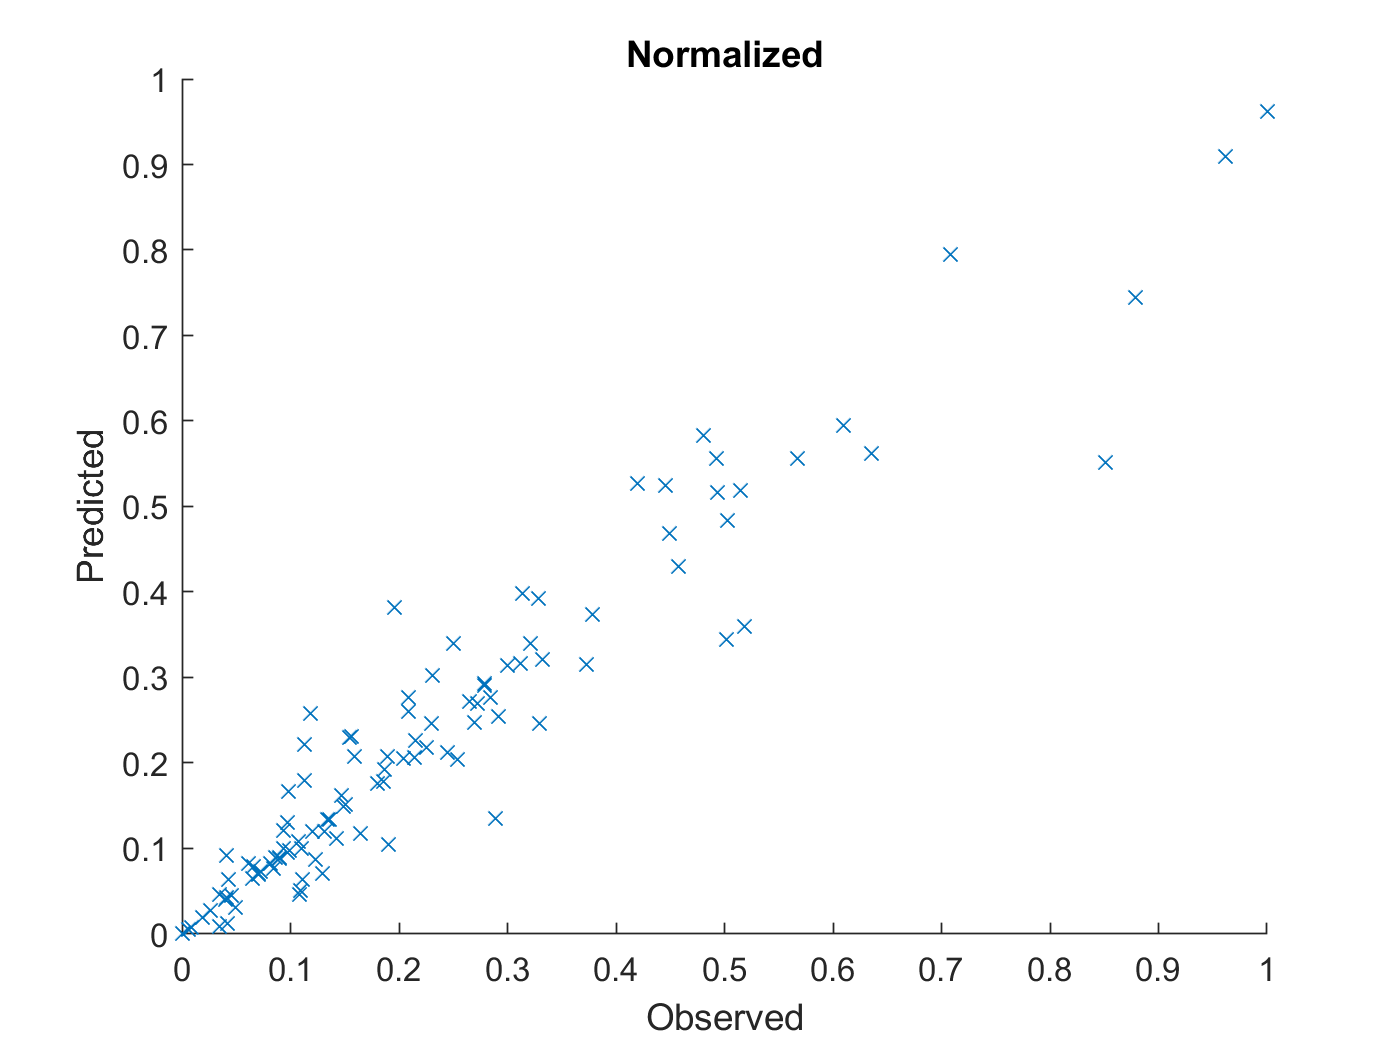

figure
hold on
plot(y_trainValid,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

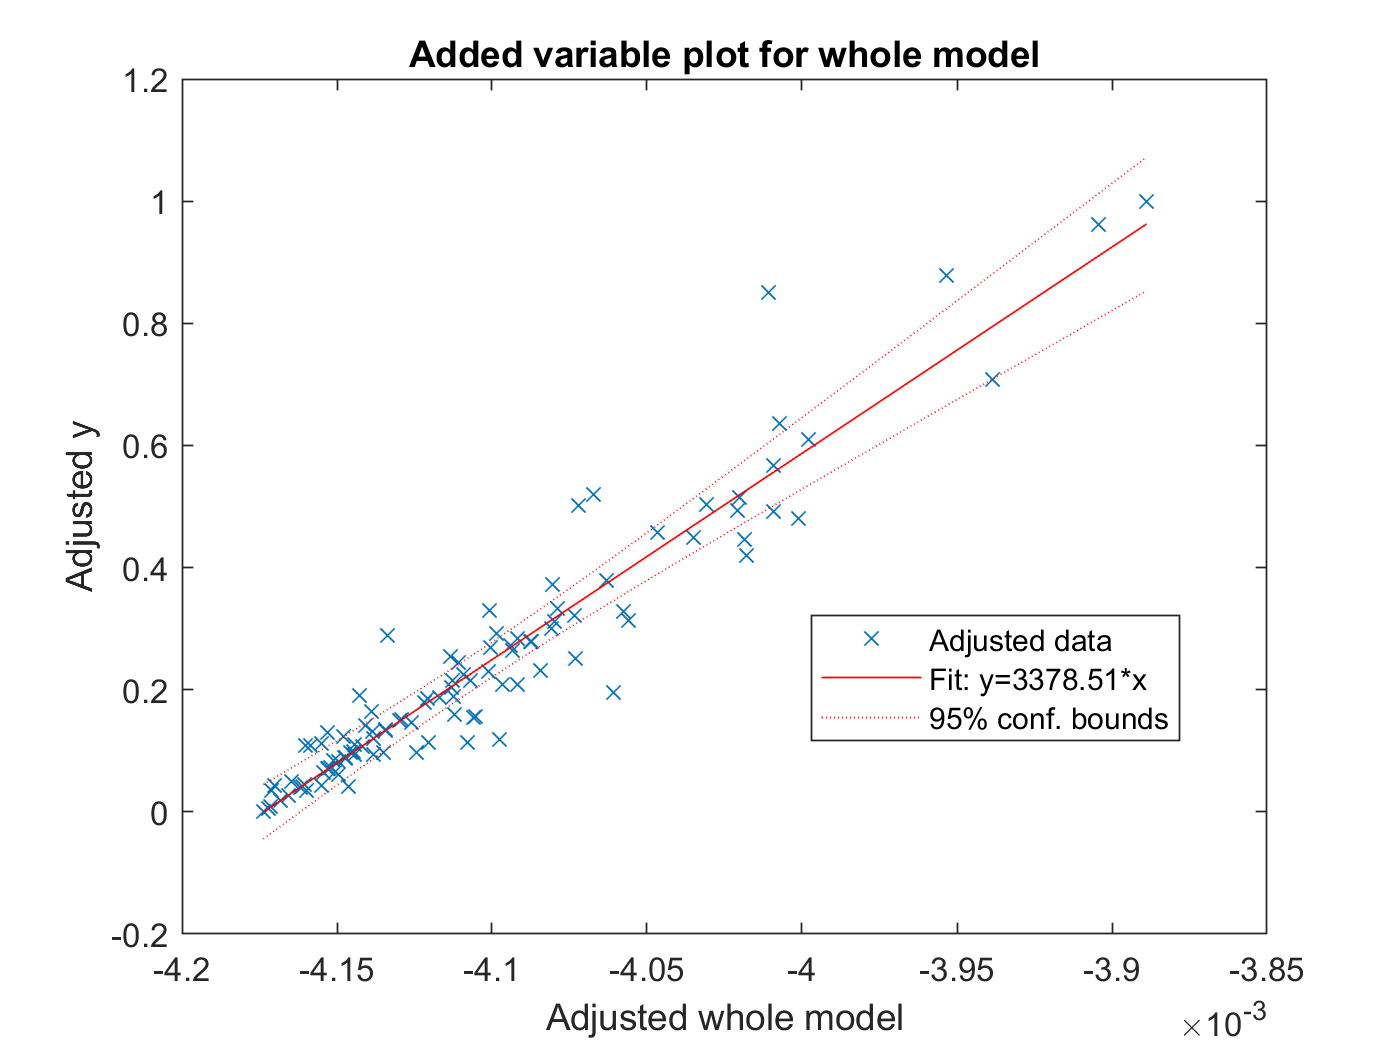


%capHat = Ic(1)

plot(mdl)

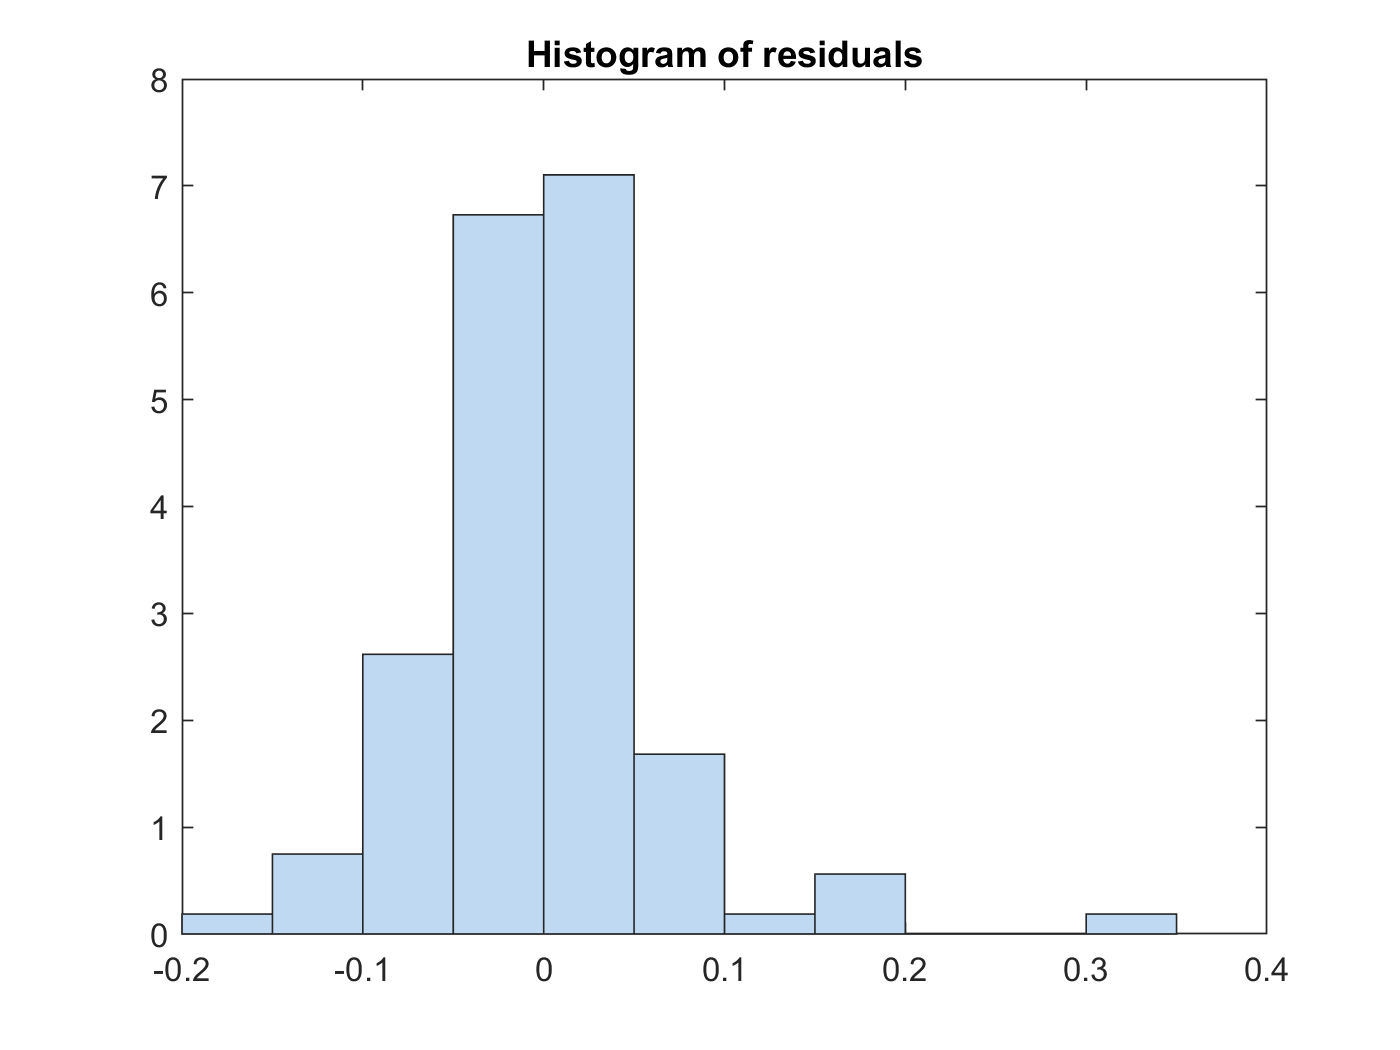

plotResiduals(mdl)

# 선형회귀 - 예측 - 100 



% yfit = predict(mdl,Ic)
yfit = predict(mdl,xFull_trainValid)

yfit =     0.0002
    0.0057
    0.0079
    0.0192
    0.0467
    0.0093
    0.0403
    0.0923
    0.0426
    0.0125


yfit_test = predict(mdl,x_test)

yfit_test =    -0.1880
    0.4526
  -24.5142
    0.0844
    0.2026
    2.7145
    0.2550
    0.3868
    0.0240
    0.4998




y= y_trainValid

y =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



% denormalize
yfit = yfit * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
y = y * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
yfit_test = yfit_test * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
y_test = y_test * yrate_IcFirst_RUL + ymin_IcFirst_RUL;


MAE = mean(abs(yfit-y))

MAE = 39.9619

adjMAE = MAE/range(y)

adjMAE = 0.0376

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.1090
    0.1150
    0.1180
    0.1290
    0.1460
    0.1460
    0.1520
    0.1529
    0.1530
    0.1540


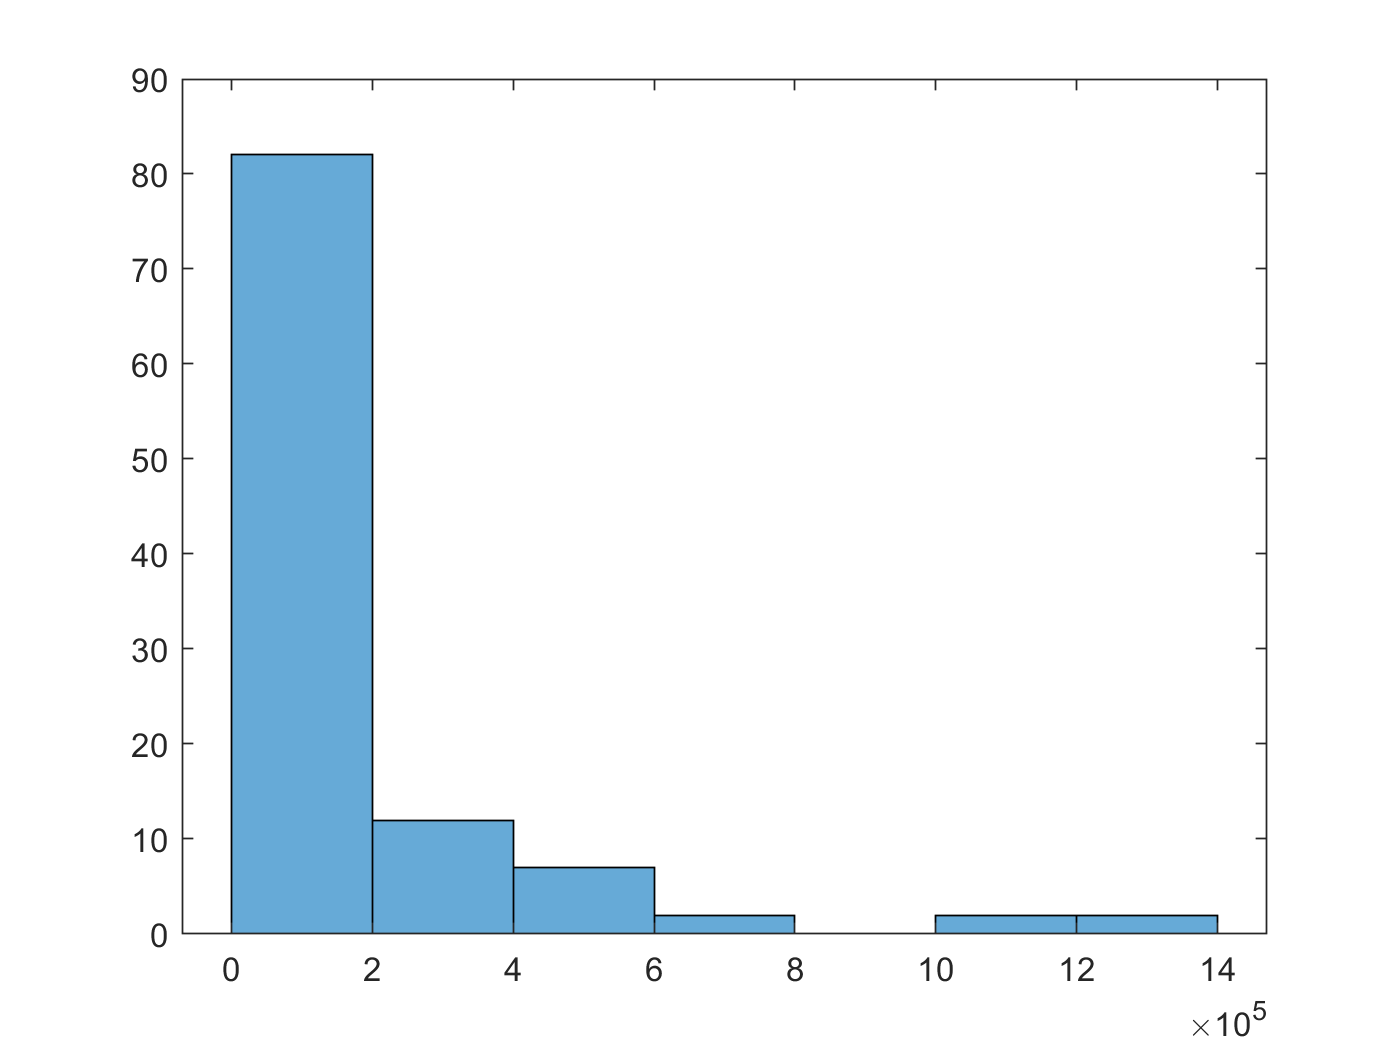

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 420.2406

(y_test - yfit_test) 

ans = 	1.0e+04 *

    0.0231
   -0.0422
    2.6128
    0.0023
   -0.0085
   -0.2722
   -0.0064
   -0.0165
    0.0279
   -0.0136


RMSE_test = sqrt(mean((y_test - yfit_test).^2))

RMSE_test = 7.5860e+03


y_test - yfit_test

ans = 	1.0e+04 *

    0.0231
   -0.0422
    2.6128
    0.0023
   -0.0085
   -0.2722
   -0.0064
   -0.0165
    0.0279
   -0.0136


y_test_diff = horzcat(y_test,(y_test-yfit_test))

y_test_diff = 	1.0e+04 *

    0.0140    0.0231
    0.0168   -0.0422
    0.0203    2.6128
    0.0222    0.0023
    0.0239   -0.0085
    0.0270   -0.2722
    0.0316   -0.0064
    0.0355   -0.0165
    0.0414    0.0279
    0.0504   -0.0136


y_test_diff_percentage = abs(y_test-yfit_test)./y_test

y_test_diff_percentage =     1.6472
    2.5099
  128.7097
    0.1050
    0.3561
   10.0808
    0.2018
    0.4640
    0.6751
    0.2695


y_test_diff_percentage_avg = sum(y_test_diff_percentage)/length(y_test_diff_percentage)

y_test_diff_percentage_avg = 12.1345

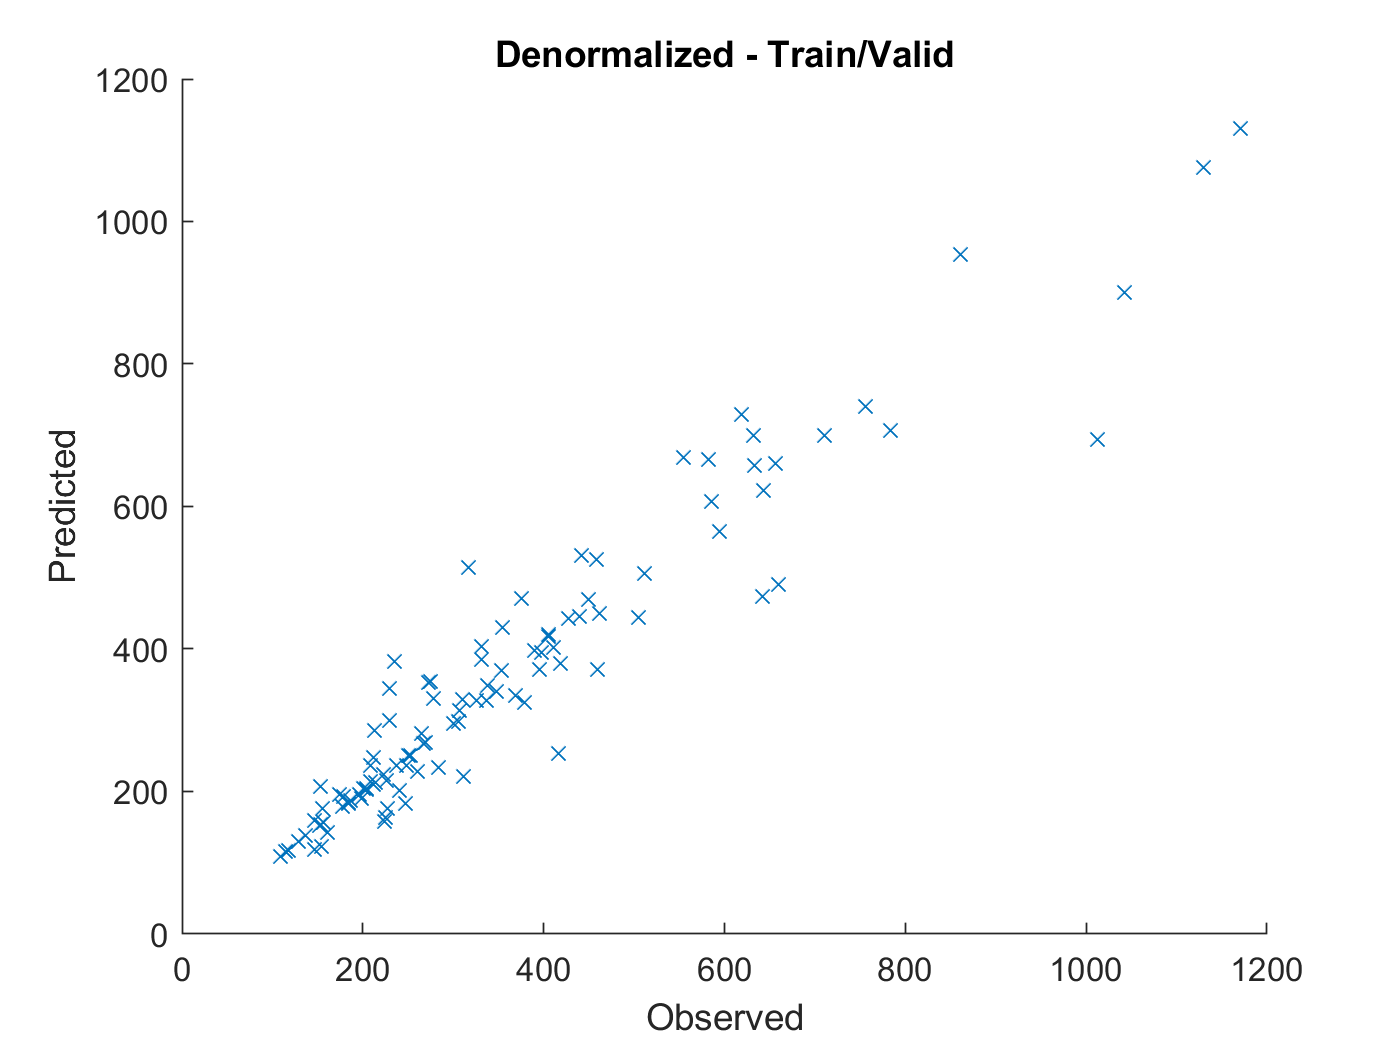

figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

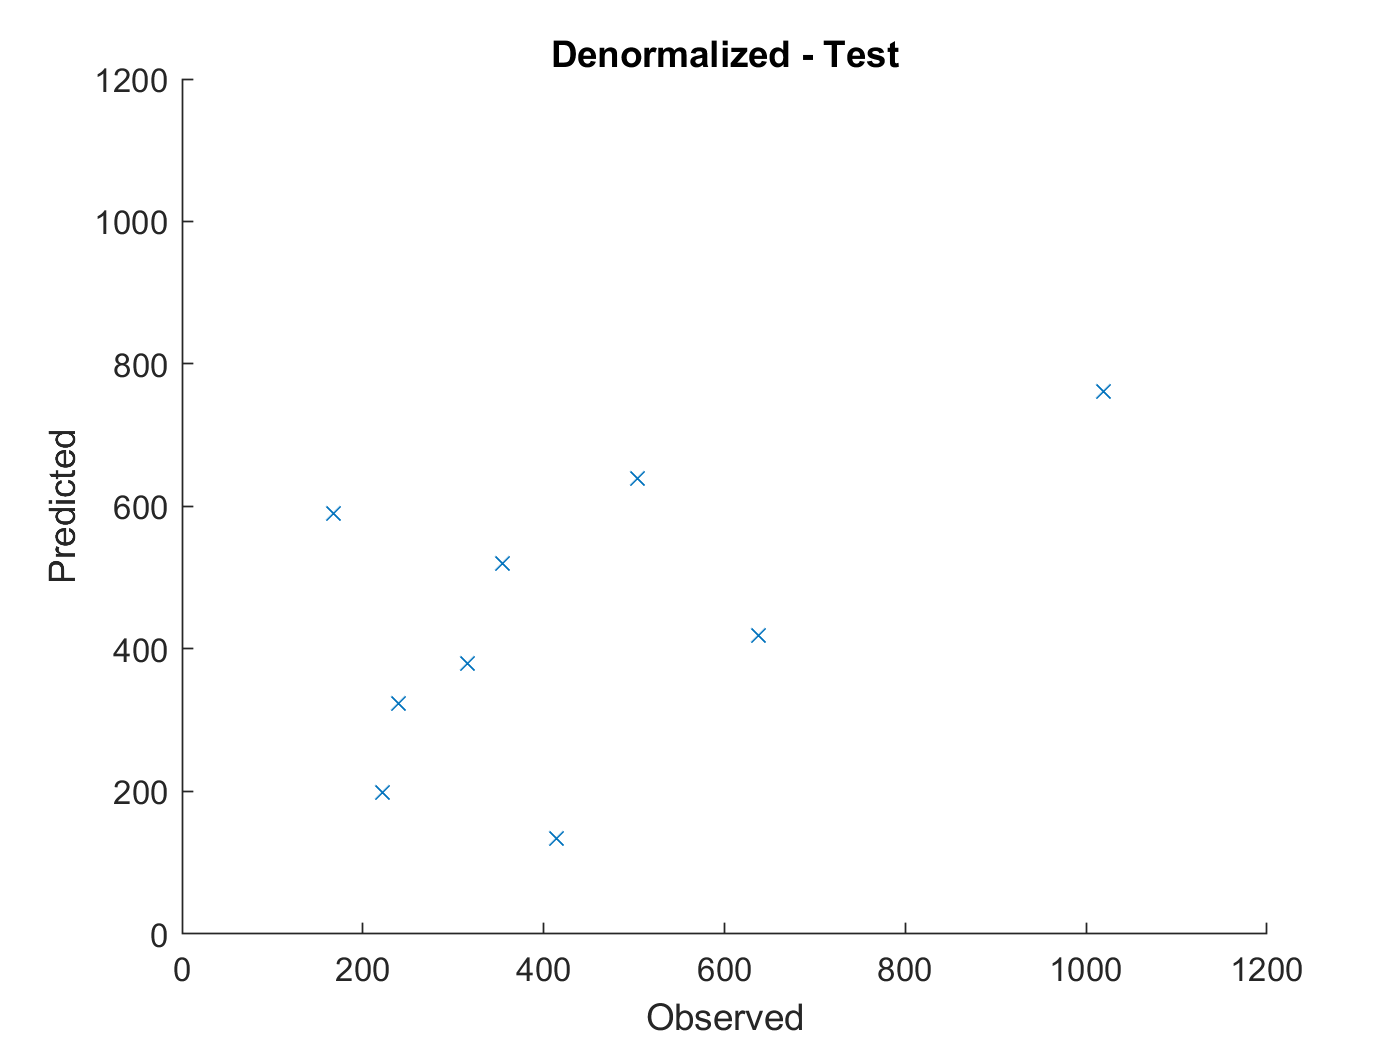


figure
hold on
plot(y_test,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'
xlim([0 1200]), ylim([0 1200])


% 테스트 셋에서는 예측이 전혀 안된다.



# 선형회귀 - 학습 - 20

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.


x_trainValid = xnorm_IcFirstSmall_RUL([idxTrain idxValid],:)

x_trainValid =     0.1998    0.2498    0.7494    0.7494    0.7485    0.7494    0.7494    0.7495    0.7494    0.7457    0.7156    0.6890    0.6641    0.6316    0.4004    0.1249    0.1050    0.0082         0         0
    0.5996    0.7499    0.7493    0.7504    0.7494    0.7506    0.7501    0.7500    0.7496    0.6143    0.4372    0.4372    0.4372    0.4372    0.3069    0.1249    0.1047    0.0096         0         0
    0.5593    0.6994    0.6995    0.6995    0.6995    0.6994    0.6994    0.6995    0.6995    0.6981    0.5809    0.4372    0.4372    0.4372    0.3075    0.1249    0.1061    0.0094         0         0
    0.5596    0.6995    0.6995    0.6995    0.6995    0.6994    0.6995    0.5259    0.5309    0.5308    0.5308    0.5308    0.5308    0.4923    0.3018    0.1249    0.1051    0.0092         0         0
    0.4896    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.6120    0.5200    0.5226    0.3259    0.1249    0.1117    0.0095 

x_test = xnorm_IcFirstSmall_RUL([idxTest],:)

x_test =     0.5995    0.7491    0.7493    0.7489    0.7490    0.7494    0.7499    0.5993    0.4996    0.4997    0.4996    0.4996    0.4996    0.4953    0.3115    0.1249    0.1078    0.0099         0         0
    0.4209    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.5906    0.5458    0.3370    0.1249    0.1144    0.0096         0         0
    0.5196    0.6236    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5933    0.5569    0.3494    0.1249    0.1171    0.0098         0         0
    0.6995    0.8743    0.8743    0.8743    0.8743    0.8743    0.8744    0.5746    0.3747    0.3747    0.3747    0.3747    0.3747    0.3747    0.2748    0.1249    0.1228    0.0127         0         0
    0.6994    0.8742    0.8744    0.8743    0.8743    0.7045    0.4497    0.4497    0.4497    0.4497    0.4496    0.4497    0.4496    0.4497    0.3198    0.1249    0.1184    0.0111       


y_trainValid = ynorm_IcFirst_RUL([idxTrain idxValid])

y_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test = ynorm_IcFirst_RUL([idxTest])

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



mdlSmall = fitlm(x_trainValid,y_trainValid)

mdlSmall = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      0.4149     0.5099     0.81369       0.41807
    x1             -0.21489    0.33095     -0.6493       0.51787
    x2              0.17704    0.39234     0.45124       0.65295
    x3             -0.50363    0.46835     -1.0753       0.28524
    x4              0.02596    0.52221    0.049712       0.96047
    x5              0.16015    0.76551      0.2092       0.83478
    x6             -0.36978    0.66408    


coeff = mdlSmall.Coefficients.Estimate

coeff =     0.4149
   -0.2149
    0.1770
   -0.5036
    0.0260
    0.1601
   -0.3698
   -0.1214
    0.4558
   -0.2644


x_trainValid(1,:)

ans =     0.1998    0.2498    0.7494    0.7494    0.7485    0.7494    0.7494    0.7495    0.7494    0.7457    0.7156    0.6890    0.6641    0.6316    0.4004    0.1249    0.1050    0.0082         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid*coeff(2:21)+coeff(1)

yhat =     0.0282
    0.0816
    0.1337
   -0.0197
    0.1144
    0.0339
    0.1922
    0.2123
    0.1194
    0.0717


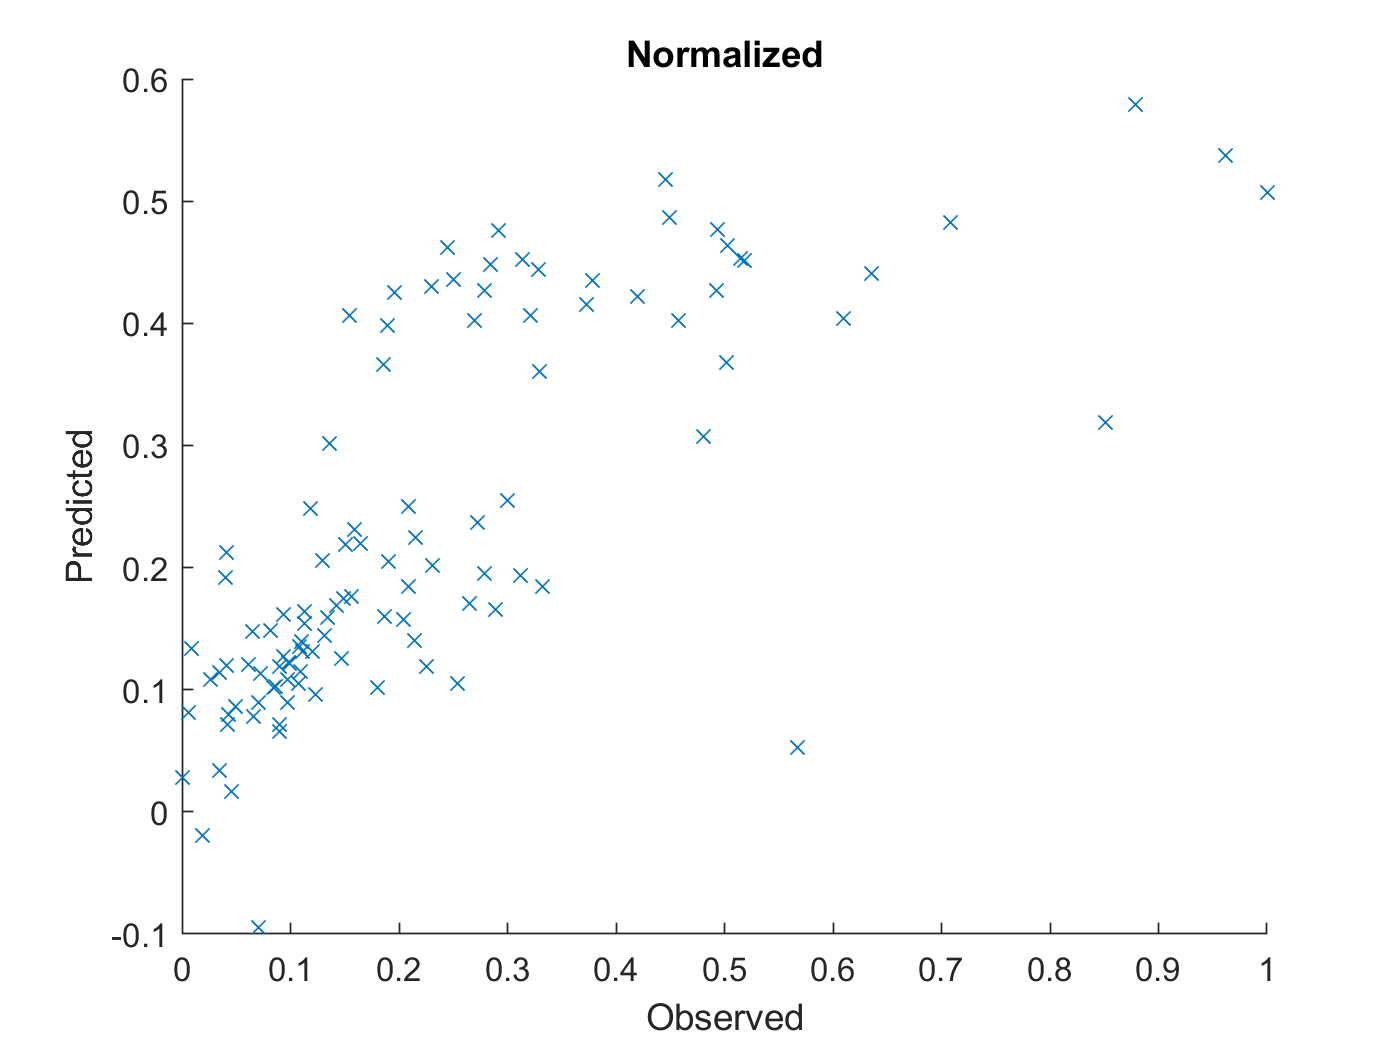


figure
hold on
plot(y_trainValid,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

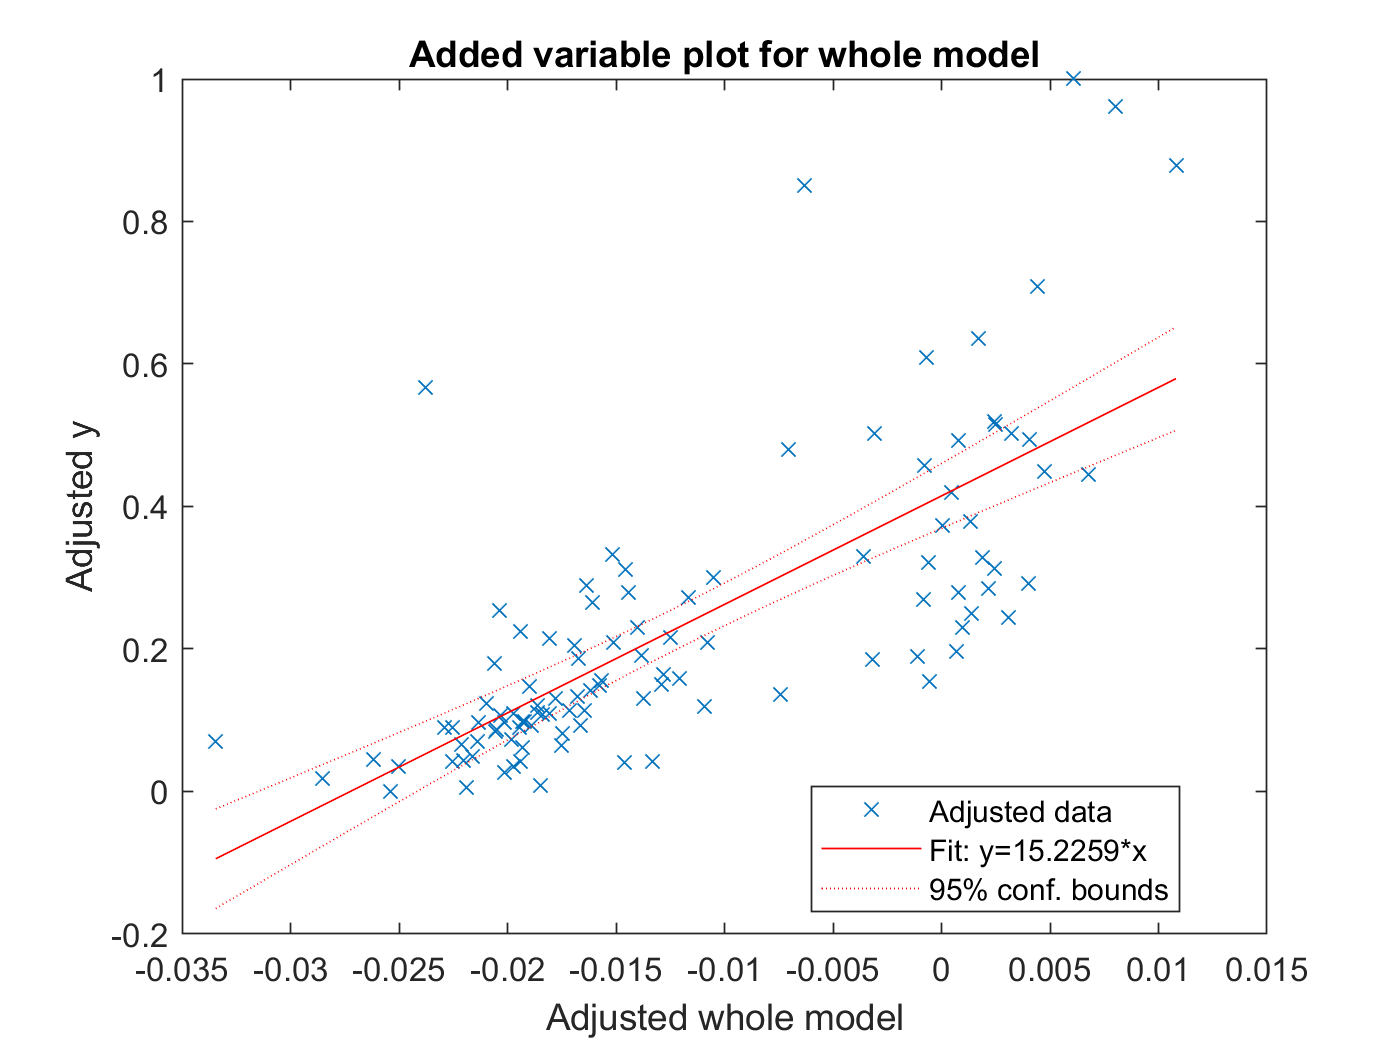


%capHat = Ic(1)

plot(mdlSmall)

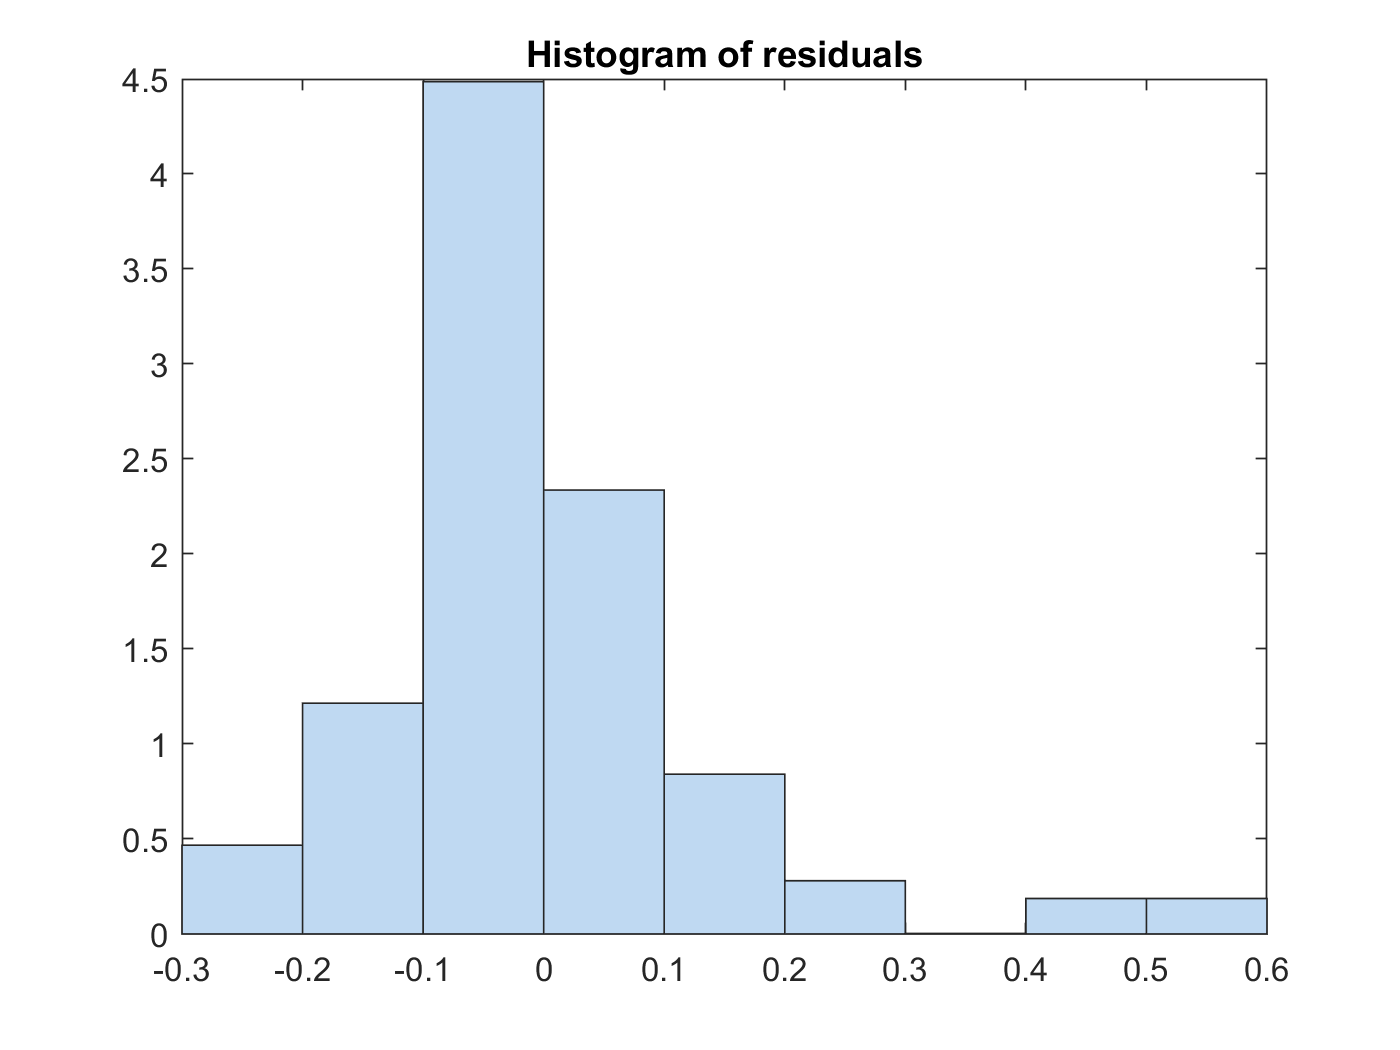

plotResiduals(mdlSmall)

ryan3_model_gen_FirstCC_RUL_desc = "ryan3_model_gen_FirstCC_RUL"

ryan3_model_gen_FirstCC_RUL_desc = "ryan3_model_gen_FirstCC_RUL"

save('ryan3_model_gen_FirstCC_RUL.mat','ryan3_model_gen_FirstCC_RUL_desc' )
save('ryan3_model_gen_FirstCC_RUL.mat','mdl' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','mdlSmall' ,'-append')

# 선형회귀 - 예측 - 20

% yfit = predict(mdl,Ic)
yfit = predict(mdlSmall,x_trainValid)

yfit =     0.0282
    0.0816
    0.1337
   -0.0197
    0.1144
    0.0339
    0.1922
    0.2123
    0.1194
    0.0717


yfit_test = predict(mdlSmall,x_test)

yfit_test =     0.0222
    0.1122
    0.1233
    0.0877
    0.1083
    0.1750
    0.1750
    0.4429
    0.3961
    0.5218




y= y_trainValid

y =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719



% denormalize
yfit = yfit * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
y = y * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
yfit_test = yfit_test * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
y_test = y_test * yrate_IcFirst_RUL + ymin_IcFirst_RUL;


MAE = mean(abs(yfit-y))

MAE = 99.5134

adjMAE = MAE/range(y)

adjMAE = 0.0937

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.1090
    0.1149
    0.1179
    0.1290
    0.1459
    0.1460
    0.1518
    0.1528
    0.1529
    0.1539


(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 420.2800


RMSE_test = sqrt(mean((y_test - yfit_test).^2))

RMSE_test = 136.1904

y_test - yfit_test

ans =     7.4567
  -60.1449
  -36.9517
   19.8146
   14.9991
  -24.8040
   21.1814
 -224.3624
 -115.6770
 -159.1358


y_test_diff = horzcat(y_test,(y_test-yfit_test))

y_test_diff = 	1.0e+03 *

    0.1400    0.0075
    0.1680   -0.0601
    0.2030   -0.0370
    0.2220    0.0198
    0.2390    0.0150
    0.2700   -0.0248
    0.3160    0.0212
    0.3550   -0.2244
    0.4140   -0.1157
    0.5040   -0.1591


y_test_diff_percentage = abs(y_test-yfit_test)./y_test

y_test_diff_percentage =     0.0533
    0.3580
    0.1820
    0.0893
    0.0628
    0.0919
    0.0670
    0.6320
    0.2794
    0.3157


y_test_diff_percentage_avg = sum(y_test_diff_percentage)/length(y_test_diff_percentage)

y_test_diff_percentage_avg = 0.2260

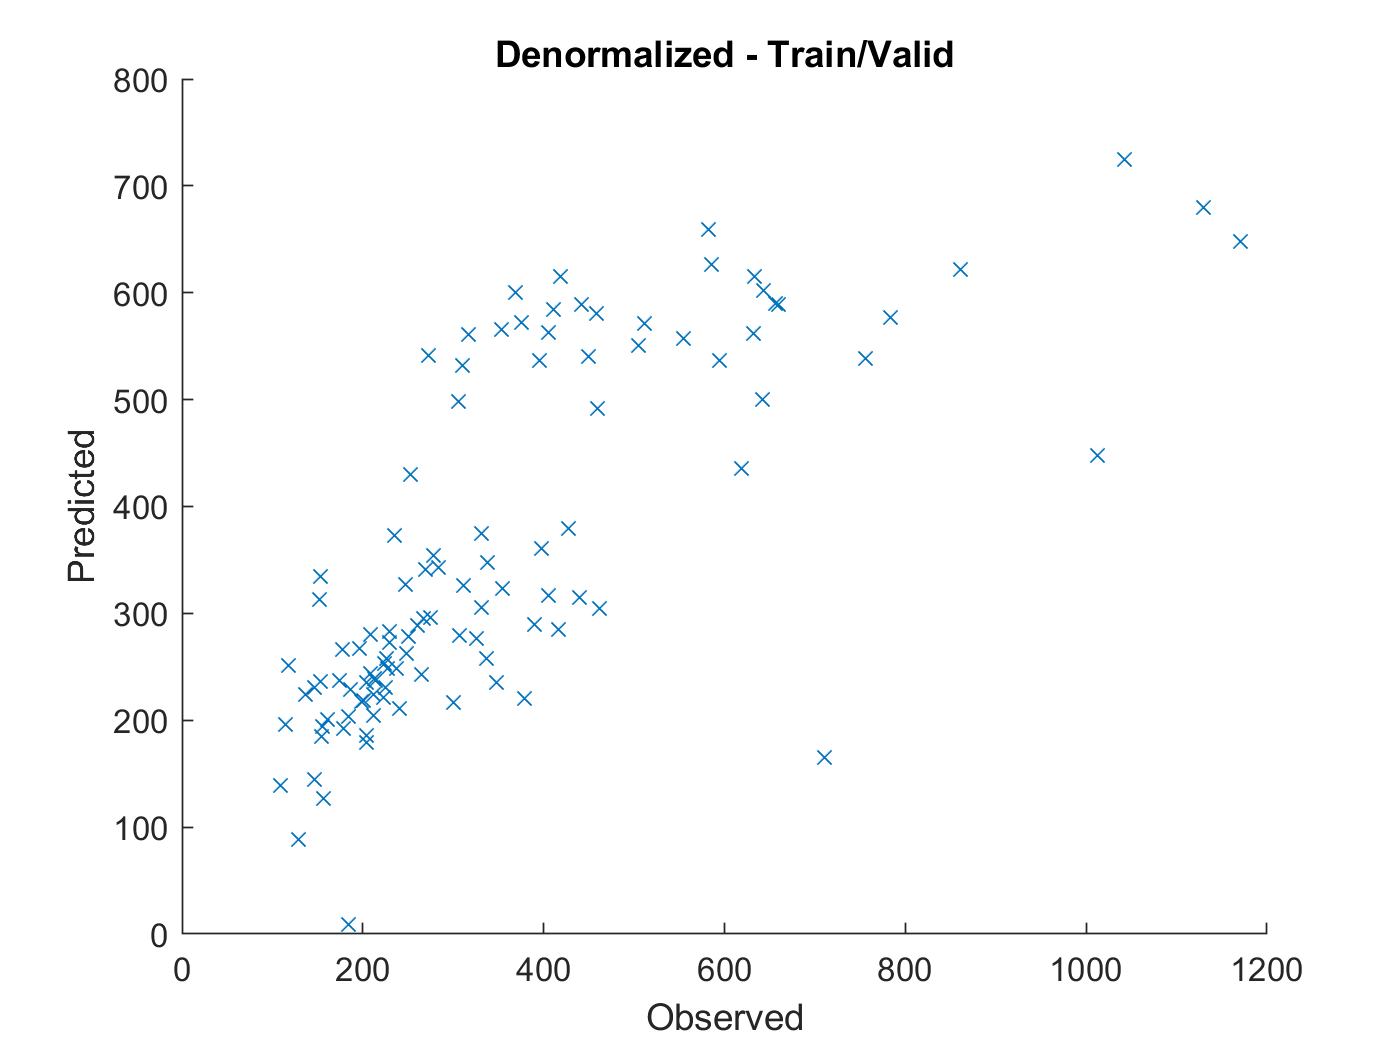


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

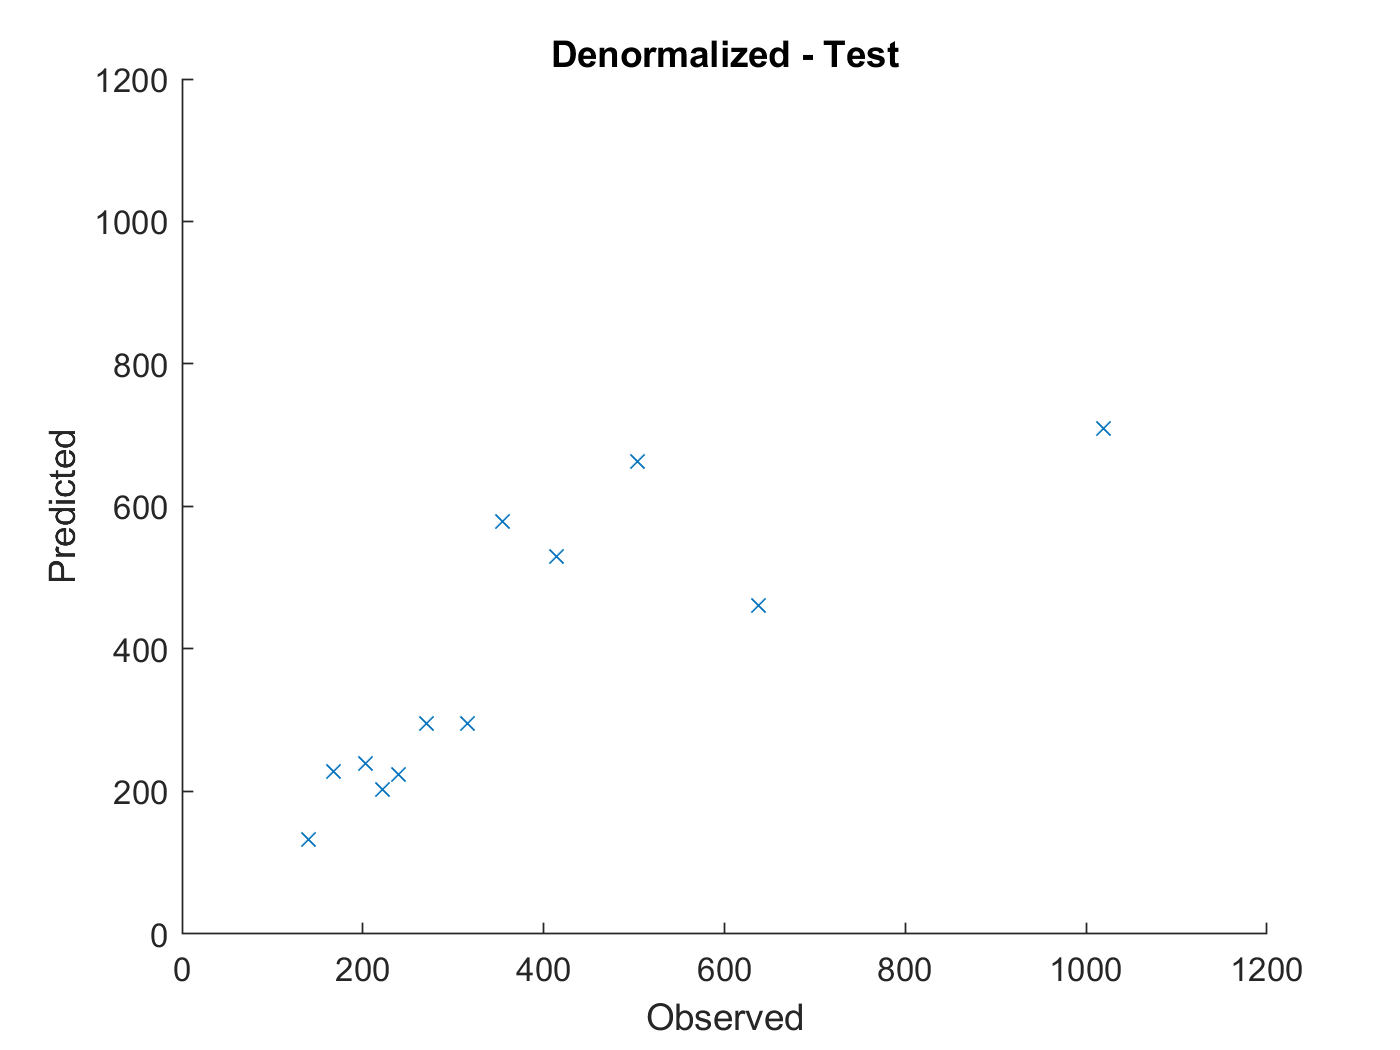


figure
hold on
plot(y_test,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'
xlim([0 1200]), ylim([0 1200])


% 테스트 셋에서는 예측이 전혀 안된다.


# FNN 학습

- netFNN1_1 = feedforwardnet(10);

- netFNN1_2 = feedforwardnet(20);

- netFNN1_3 = feedforwardnet(100);

- netFNN2_1 = feedforwardnet([20,20]);

- netFNN2_2 = feedforwardnet([100,20]);

- netFNN3_1 = feedforwardnet([20,20,20]);

- netFNN4_1 = feedforwardnet([20,20,20,20]);

- netFNN4_1 = feedforwardnet([20,20,20,20,20]);

- epoc = 300 


netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainRand;
netFNN1_1.divideParam.valInd = idxValidRand;
netFNN1_1.divideParam.testInd = idxTestRand; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainRand;
netFNN1_2.divideParam.valInd = idxValidRand;
netFNN1_2.divideParam.testInd = idxTestRand; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_2 = train(netFNN1_2, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.




netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainRand;
netFNN1_3.divideParam.valInd = idxValidRand;
netFNN1_3.divideParam.testInd = idxTestRand; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_3 = train(netFNN1_3, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.



netFNN2_1 = feedforwardnet([20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = tr.trainInd;
netFNN2_1.divideParam.valInd = tr.valInd;
netFNN2_1.divideParam.testInd = tr.testInd; 

netFNN2_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
netFNN2_1 = train(netFNN2_1, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([100,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = tr.trainInd;
netFNN2_2.divideParam.valInd = tr.valInd;
netFNN2_2.divideParam.testInd = tr.testInd; 

netFNN2_2.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
netFNN2_2 = train(netFNN2_1, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = tr.trainInd;
netFNN3_1.divideParam.valInd = tr.valInd;
netFNN3_1.divideParam.testInd = tr.testInd; 

netFNN3_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
netFNN3_1 = train(netFNN3_1, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_1)

netFNN4_1 = feedforwardnet([20,20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = tr.trainInd;
netFNN4_1.divideParam.valInd = tr.valInd;
netFNN4_1.divideParam.testInd = tr.testInd; 

netFNN4_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
netFNN4_1 = train(netFNN3_1, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_1)

netFNN5_1 = feedforwardnet([20,20,20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = tr.trainInd;
netFNN5_1.divideParam.valInd = tr.valInd;
netFNN5_1.divideParam.testInd = tr.testInd; 

netFNN5_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
netFNN5_1 = train(netFNN3_1, xnorm_IcFirstSmall_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_1)

# FNN 예측

pFNN1_1 = netFNN1_1(xnorm_IcFirstSmall_RUL(tr.testInd, :)');
pFNN1_2 = netFNN1_2(xnorm_IcFirstSmall_RUL(tr.testInd, :)');
pFNN1_3 = netFNN1_3(xnorm_IcFirstSmall_RUL(tr.testInd, :)');
pFNN2_1 = netFNN2_1(xnorm_IcFirstSmall_RUL(tr.testInd, :)');
pFNN2_2 = netFNN2_2(xnorm_IcFirstSmall_RUL(tr.testInd, :)');
pFNN3_1 = netFNN3_1(xnorm_IcFirstSmall_RUL(tr.testInd, :)');
pFNN4_1 = netFNN4_1(xnorm_IcFirstSmall_RUL(tr.testInd, :)');
pFNN5_1 = netFNN5_1(xnorm_IcFirstSmall_RUL(tr.testInd, :)');

ytest = ynorm_IcFirst_RUL(tr.testInd, :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_1_hat = pFNN1_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_2_hat = pFNN1_2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_3_hat = pFNN1_3 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN2_1_hat = pFNN2_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN2_2_hat = pFNN2_2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN3_1_hat = pFNN3_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN4_1_hat = pFNN4_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN5_1_hat = pFNN5_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 135.0839

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 105.5584

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 135.7976

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 127.3888

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 127.3888

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 73.8369

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 73.8369

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 73.8369

y_test_diff_percentage_FNN1_1_hat_avg = sum(abs(y_test'-pFNN1_1_hat)./y_test')/length(abs(y_test'-pFNN1_1_hat)./y_test')

y_test_diff_percentage_FNN1_1_hat_avg = 0.3794

y_test_diff_percentage_FNN1_2_hat_avg = sum(abs(y_test'-pFNN1_2_hat)./y_test')/length(abs(y_test'-pFNN1_2_hat)./y_test')

y_test_diff_percentage_FNN1_2_hat_avg = 0.3672

y_test_diff_percentage_FNN1_3_hat_avg = sum(abs(y_test'-pFNN1_3_hat)./y_test')/length(abs(y_test'-pFNN1_3_hat)./y_test')

y_test_diff_percentage_FNN1_3_hat_avg = 0.4737

y_test_diff_percentage_FNN2_1_hat_avg = sum(abs(y_test'-pFNN2_1_hat)./y_test')/length(abs(y_test'-pFNN2_1_hat)./y_test')

y_test_diff_percentage_FNN2_1_hat_avg = 0.3654

y_test_diff_percentage_FNN2_2_hat_avg = sum(abs(y_test'-pFNN2_2_hat)./y_test')/length(abs(y_test'-pFNN2_2_hat)./y_test')

y_test_diff_percentage_FNN2_2_hat_avg = 0.3654

y_test_diff_percentage_FNN3_1_hat_avg = sum(abs(y_test'-pFNN3_1_hat)./y_test')/length(abs(y_test'-pFNN3_1_hat)./y_test')

y_test_diff_percentage_FNN3_1_hat_avg = 0.2965

y_test_diff_percentage_FNN4_1_hat_avg = sum(abs(y_test'-pFNN4_1_hat)./y_test')/length(abs(y_test'-pFNN4_1_hat)./y_test')

y_test_diff_percentage_FNN4_1_hat_avg = 0.2965

y_test_diff_percentage_FNN5_1_hat_avg = sum(abs(y_test'-pFNN5_1_hat)./y_test')/length(abs(y_test'-pFNN5_1_hat)./y_test')

y_test_diff_percentage_FNN5_1_hat_avg = 0.2965

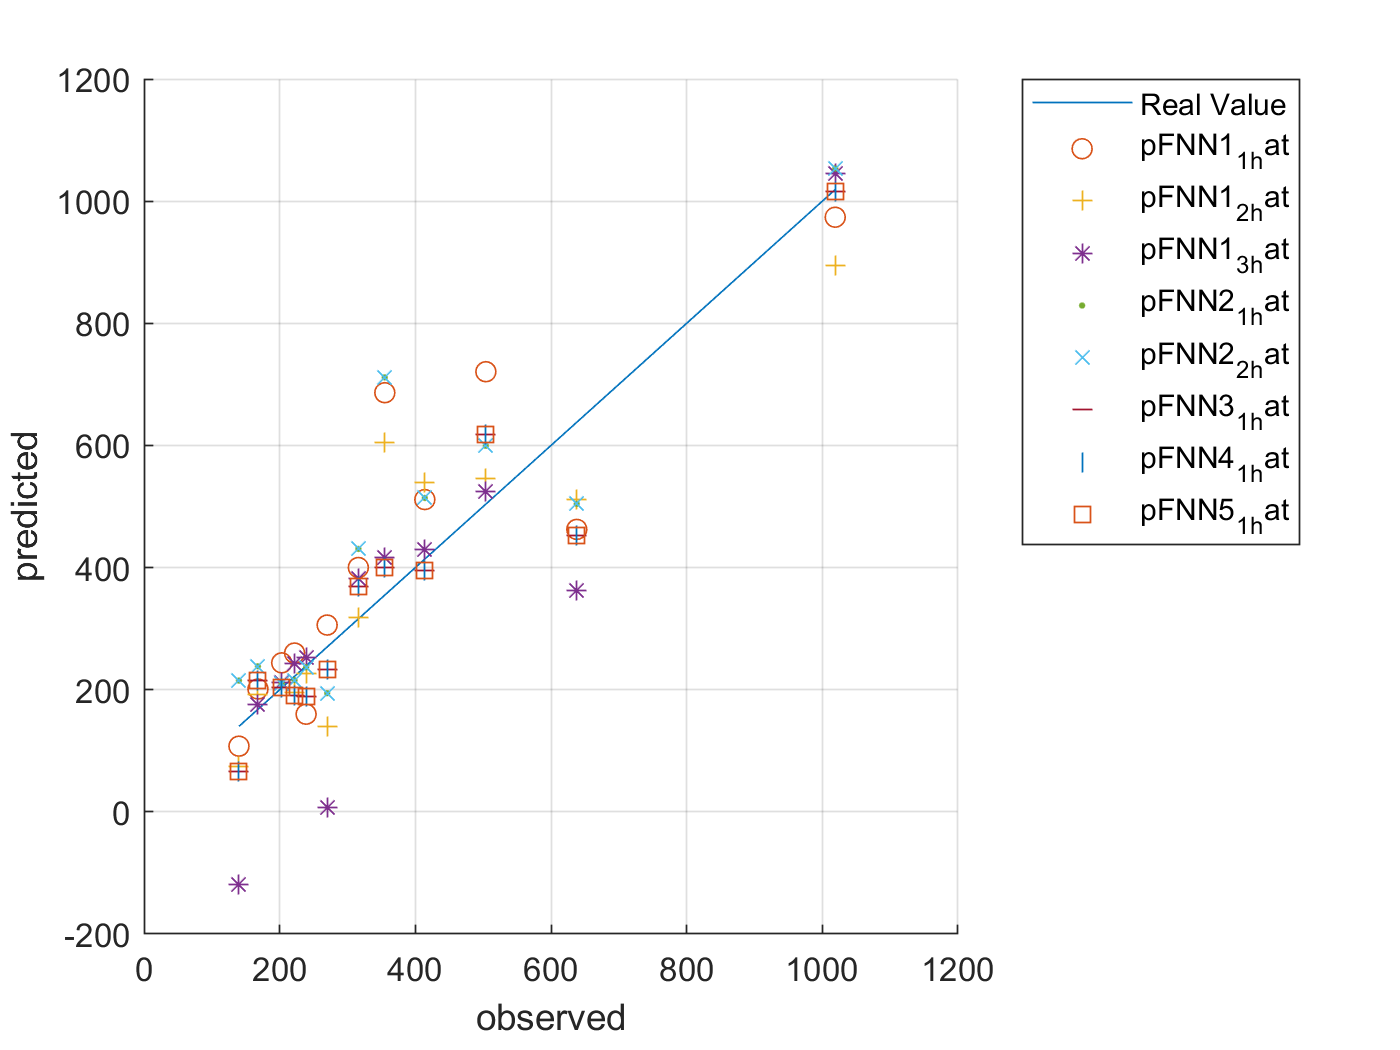



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')

save('ryan3_model_gen_FirstCC_RUL.mat','netFNN1_1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netFNN1_2' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netFNN1_3' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netFNN2_1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netFNN2_2' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netFNN3_1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netFNN4_1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netFNN5_1' ,'-append')

pFNN1_1_self = netFNN1_1(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');
pFNN1_2_self = netFNN1_2(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');
pFNN1_3_self = netFNN1_3(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');
pFNN2_1_self = netFNN2_1(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');
pFNN2_2_self = netFNN2_2(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');
pFNN3_1_self = netFNN3_1(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');
pFNN4_1_self = netFNN4_1(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');
pFNN5_1_self = netFNN5_1(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)');

ytrain_self = ynorm_IcFirst_RUL([tr.trainInd tr.valInd], :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_1_self_hat = pFNN1_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_2_self_hat = pFNN1_2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_3_self_hat = pFNN1_3_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN2_1_self_hat = pFNN2_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN2_2_self_hat = pFNN2_2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN3_1_self_hat = pFNN3_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN4_1_self_hat = pFNN4_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN5_1_self_hat = pFNN5_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 130.3829

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 150.6447

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 100.4714

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 127.4195

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 127.4195

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 76.0977

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 76.0977

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 76.0977

y_test_diff_percentage_FNN1_1_self_hat_avg = sum(abs(ytrain_self'-pFNN1_1_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN1_1_self_hat)./ytrain_self')

y_test_diff_percentage_FNN1_1_self_hat_avg = 0.2310

ytrain_self_diff_percentage_FNN1_2_self_hat_avg = sum(abs(ytrain_self'-pFNN1_2_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN1_2_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN1_2_self_hat_avg = 0.2994

ytrain_self_diff_percentage_FNN1_3_self_hat_avg = sum(abs(ytrain_self'-pFNN1_3_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN1_3_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN1_3_self_hat_avg = 0.1308

ytrain_self_diff_percentage_FNN2_1_self_hat_avg = sum(abs(ytrain_self'-pFNN2_1_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN2_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN2_1_self_hat_avg = 0.2681

ytrain_self_diff_percentage_FNN2_2_self_hat_avg = sum(abs(ytrain_self'-pFNN2_2_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN2_2_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN2_2_self_hat_avg = 0.2681

ytrain_self_diff_percentage_FNN3_1_self_hat_avg = sum(abs(ytrain_self'-pFNN3_1_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN3_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN3_1_self_hat_avg = 0.1156

ytrain_self_diff_percentage_FNN4_1_self_hat_avg = sum(abs(ytrain_self'-pFNN4_1_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN4_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN4_1_self_hat_avg = 0.1156

ytrain_self_diff_percentage_FNN5_1_self_hat_avg = sum(abs(ytrain_self'-pFNN5_1_self_hat)./ytrain_self')/length(abs(ytrain_self'-pFNN5_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN5_1_self_hat_avg = 0.1156

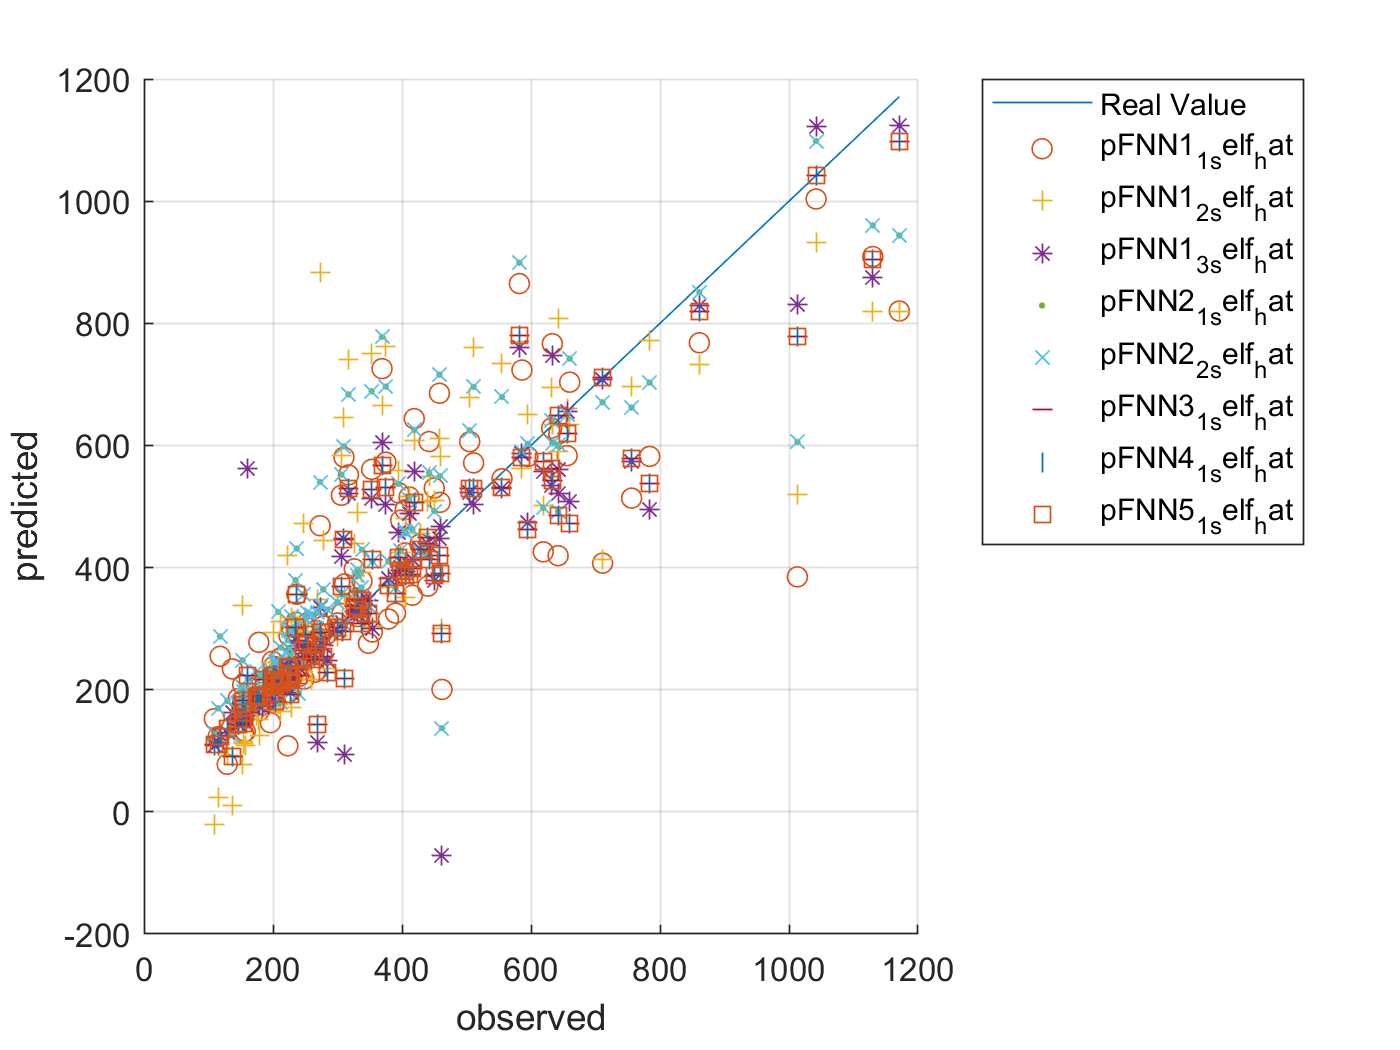




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

filterSize = 3;
numFilters = 32;
numFCN = 1;
cc_input_size = 20;

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.24 |         0.30 |       0.0300 |       0.0435 |          0.0010 |
|      50 |          50 |       00:00:07 |         0.14 |         0.23 |       0.0103 |       0.0260 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.13 |         0.22 |       0.0084 |       0.0250 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.12 |         0.22 |       0.0066 |   

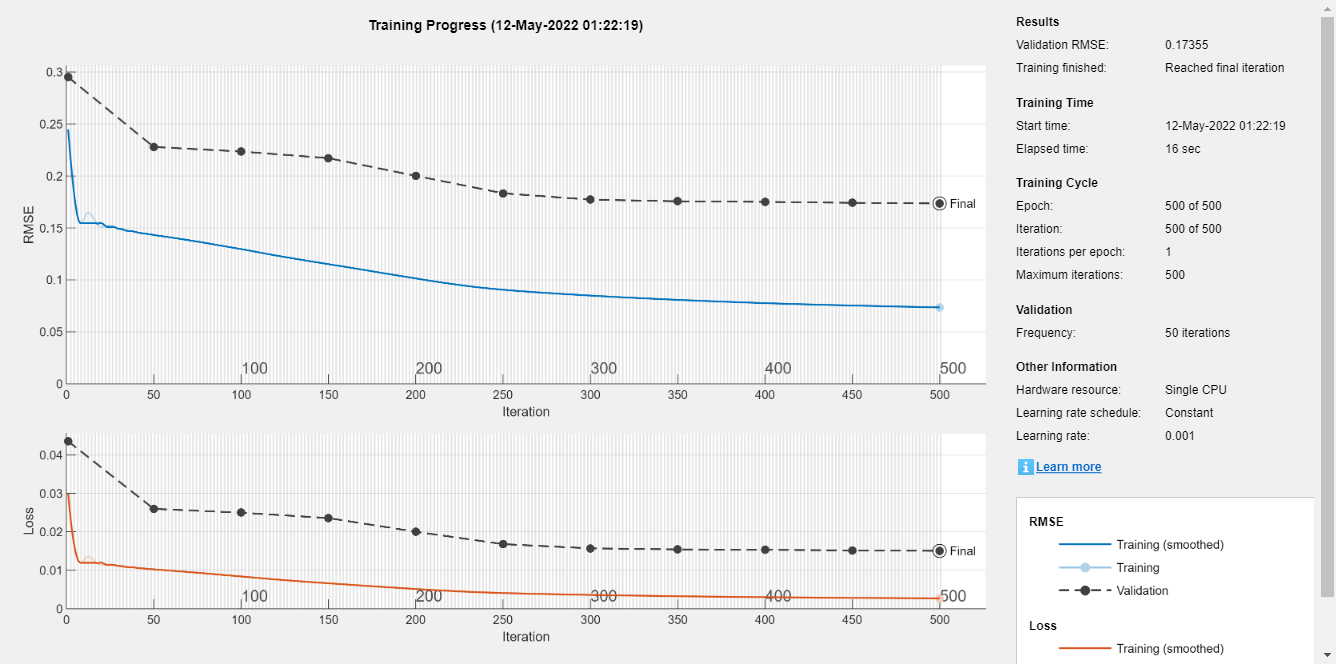



layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm_IcFirstSmall_RUL', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm_IcFirst_RUL);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);




- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.29 |         0.28 |       0.0413 |       0.0399 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.19 |         0.22 |       0.0190 |       0.0253 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.17 |         0.22 |       0.0146 |       0.0252 |          0.0010 |
|     150 |         150 |       00:00:08 |         0.15 |         0.21 |       0.0114 |   

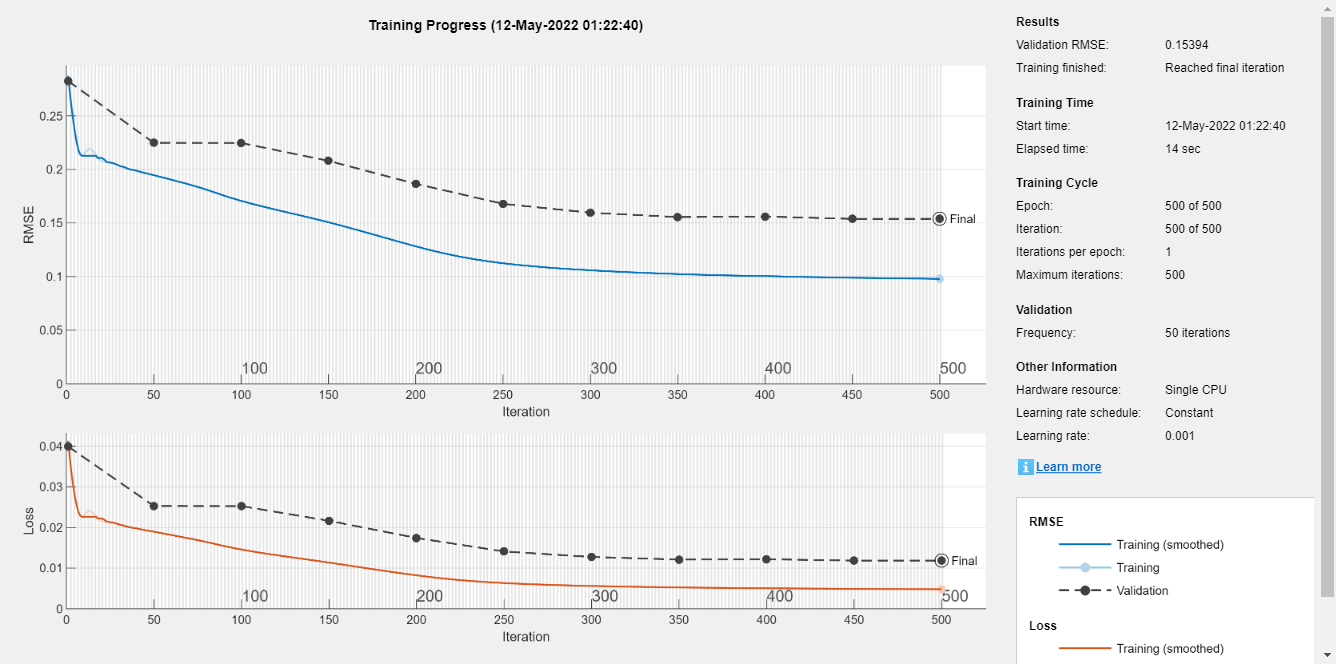

layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.24 |         0.26 |       0.0298 |       0.0344 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.19 |         0.22 |       0.0174 |       0.0245 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.18 |         0.22 |       0.0157 |       0.0244 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.17 |         0.22 |       0.0144 |   

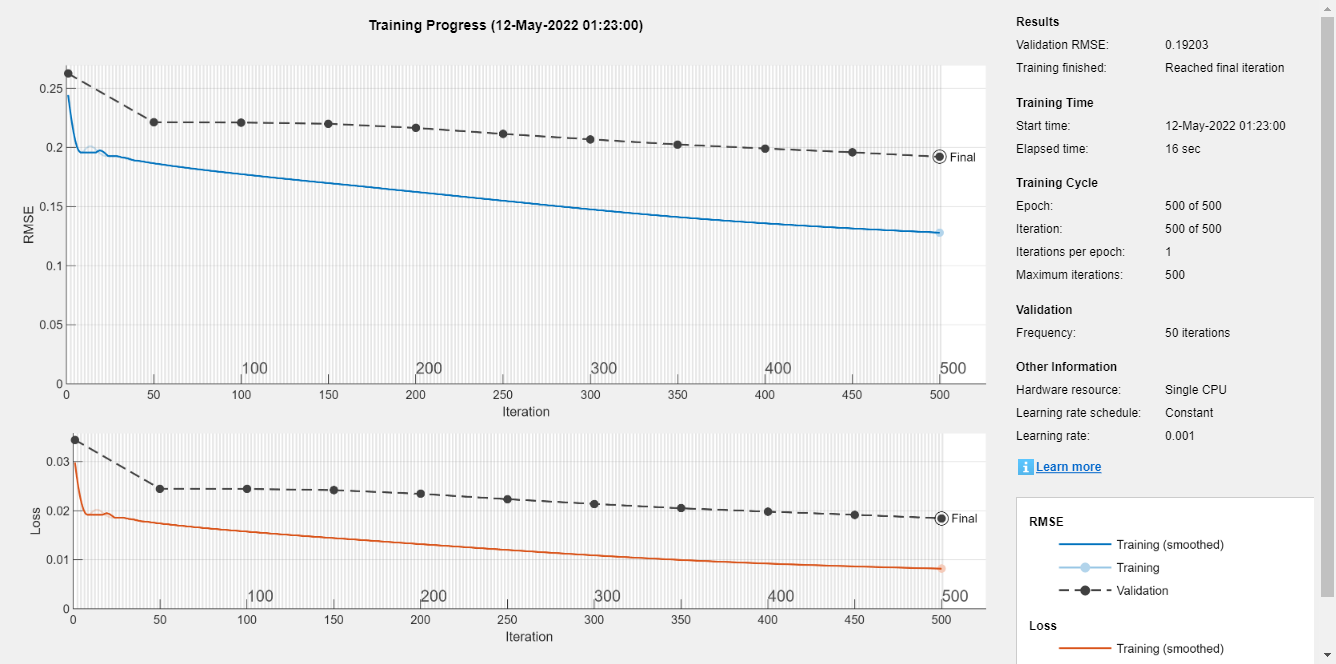





layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.57 |         0.26 |       0.1602 |       0.0340 |          0.0010 |
|      50 |          50 |       00:00:08 |         0.19 |         0.25 |       0.0178 |       0.0309 |          0.0010 |
|     100 |         100 |       00:00:12 |         0.18 |         0.24 |       0.0163 |       0.0294 |          0.0010 |
|     150 |         150 |       00:00:13 |         0.17 |         0.24 |       0.0151 |   

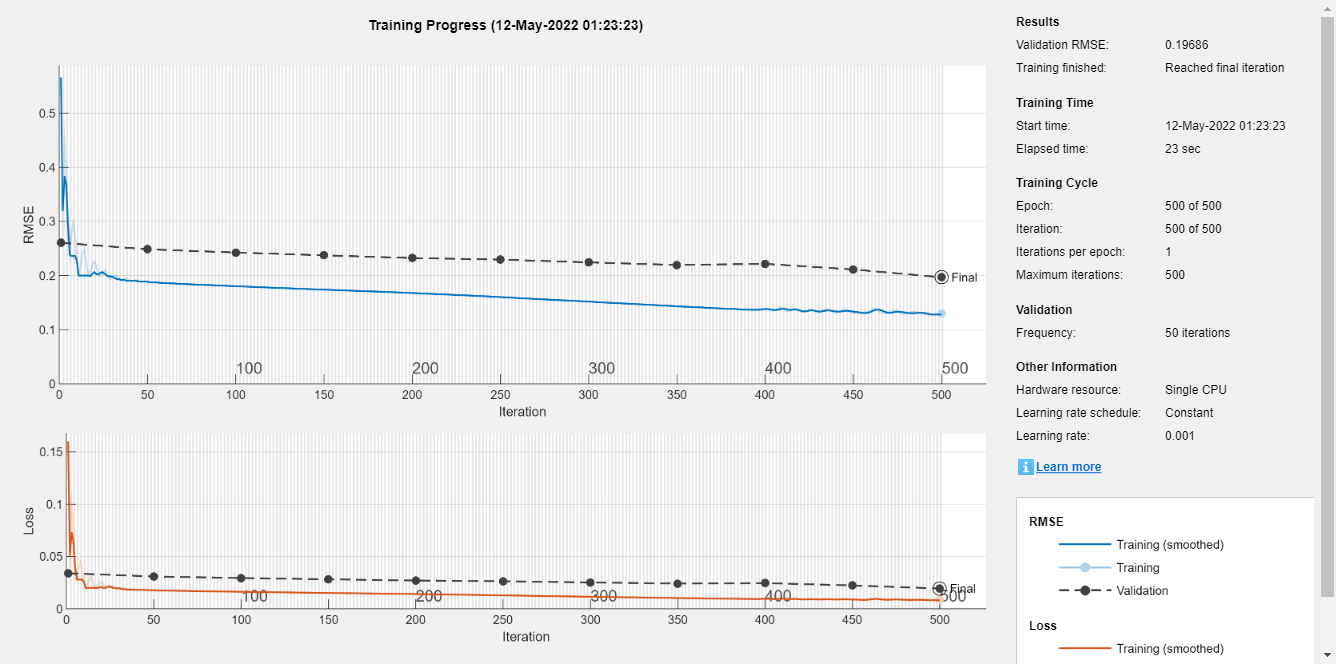



layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.68 |         1.70 |       0.2305 |       1.4472 |          0.0010 |
|      50 |          50 |       00:00:13 |         0.18 |         0.28 |       0.0167 |       0.0399 |          0.0010 |
|     100 |         100 |       00:00:15 |         0.17 |         0.28 |       0.0136 |       0.0382 |          0.0010 |
|     150 |         150 |       00:00:17 |         0.16 |         0.28 |       0.0122 |   

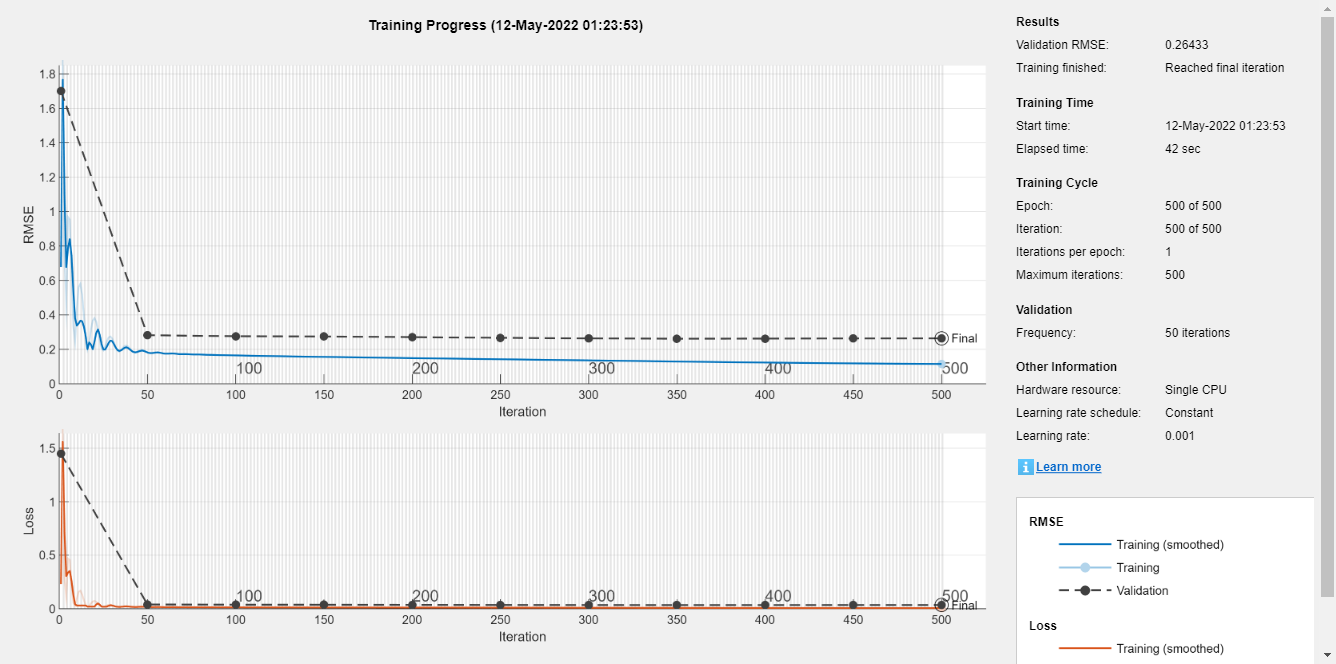


layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);

# CNN 예측

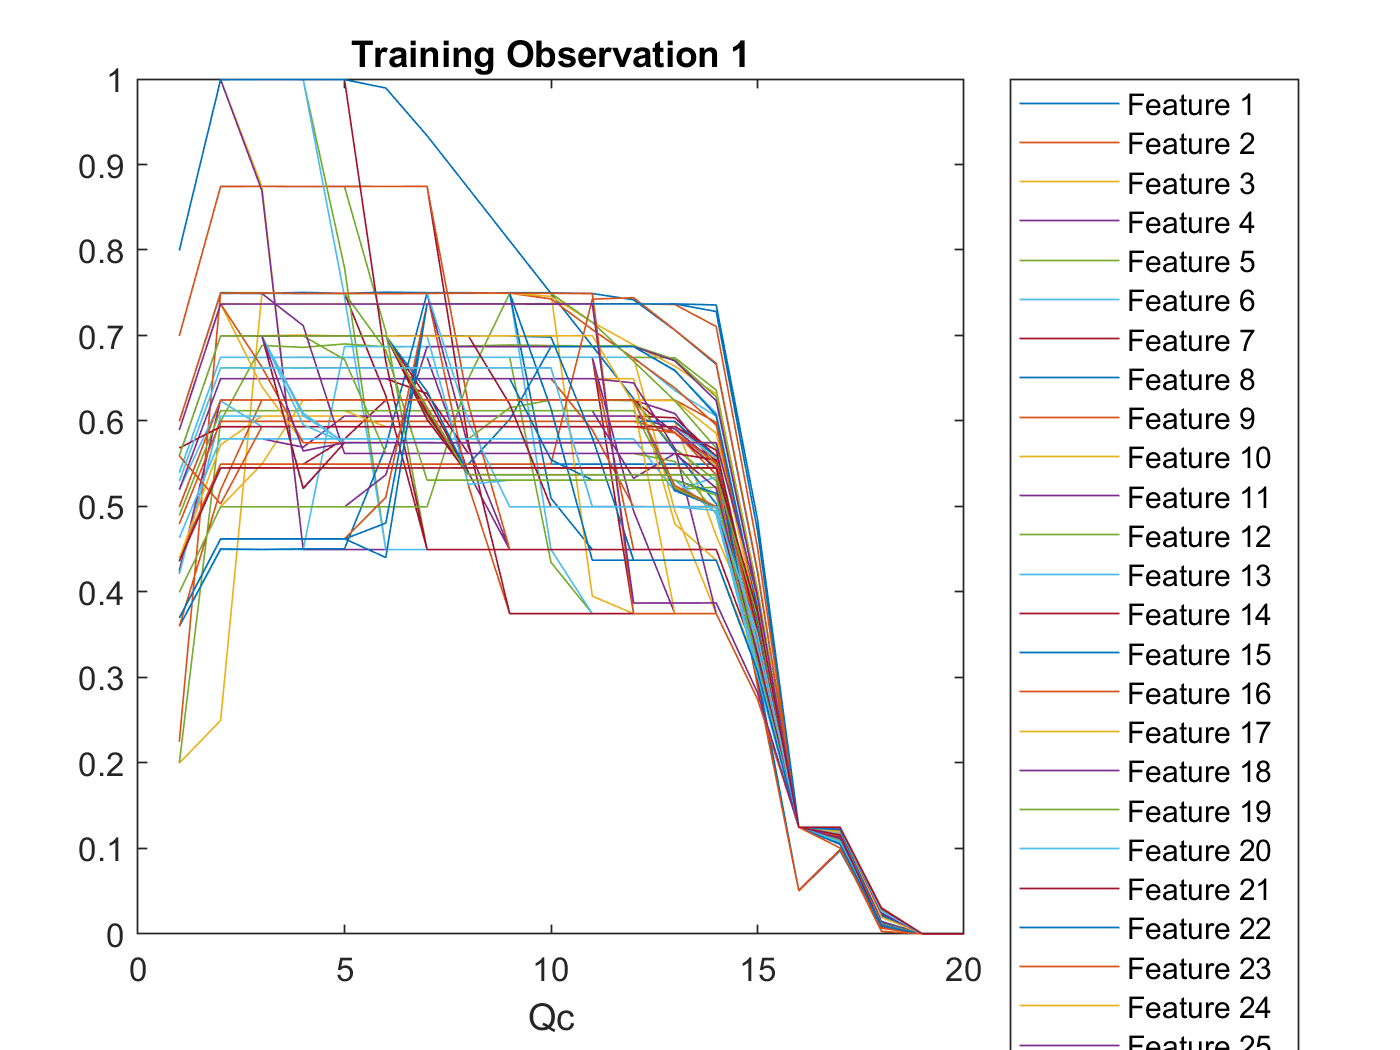

figure
plot(xnorm_IcFirstSmall_RUL')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm_IcFirstSmall_RUL,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")



cellx = num2cell(xnorm_IcFirstSmall_RUL(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d)

pCNN2_1 = 12×1 single column vector
    0.1422
    0.1030
    0.0966
    0.0679
    0.0595
    0.1009
    0.0817
    0.3857
    0.4093
    0.3121


pCNN2_2 = predict(netCNN2_2, x_4d)

pCNN2_2 = 12×1 single column vector
    0.0990
    0.0983
    0.0525
    0.2012
    0.0594
    0.1242
   -0.0533
    0.3716
    0.4644
    0.4843


pCNN2_3 = predict(netCNN2_3, x_4d)

pCNN2_3 = 12×1 single column vector
    0.2573
    0.1470
    0.2206
    0.0730
    0.0936
    0.0940
    0.0619
    0.3129
    0.2993
    0.5431


pCNN2_4 = predict(netCNN2_4, x_4d)

pCNN2_4 = 12×1 single column vector
    0.2527
    0.1250
    0.1505
   -0.0589
    0.1464
    0.2020
    0.0956
    0.3846
    0.3856
    0.3043


pCNN1_1 = predict(netCNN1_1, x_4d)

pCNN1_1 = 12×1 single column vector
    0.1691
    0.3598
    0.1028
    0.2395
    0.1037
    0.1624
    0.0601
    0.3826
    0.4777
    0.3940





ytest = ynorm_IcFirst_RUL(tr.testInd, :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_1_hat = pCNN2_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_2_hat = pCNN2_2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_3_hat = pCNN2_3 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_4_hat = pCNN2_4 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN1_1_hat = pCNN1_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
180.9039

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
141.9561

rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))

rmse_pCNN2_3_hat = single
143.3761

rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))

rmse_pCNN2_4_hat = single
145.7082

rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
194.5246

y_test_diff_percentage_CNN2_1_hat_avg = sum(abs(y_test'-pCNN2_1_hat')./y_test')/length(abs(y_test'-pCNN2_1_hat')./y_test')

y_test_diff_percentage_CNN2_1_hat_avg = single
0.3293

y_test_diff_percentage_CNN2_2_hat_avg = sum(abs(y_test'-pCNN2_2_hat')./y_test')/length(abs(y_test'-pCNN2_2_hat')./y_test')

y_test_diff_percentage_CNN2_2_hat_avg = single
0.3390

y_test_diff_percentage_CNN2_3_hat_avg = sum(abs(y_test'-pCNN2_3_hat')./y_test')/length(abs(y_test'-pCNN2_3_hat')./y_test')

y_test_diff_percentage_CNN2_3_hat_avg = single
0.4381

y_test_diff_percentage_CNN2_4_hat_avg = sum(abs(y_test'-pCNN2_4_hat')./y_test')/length(abs(y_test'-pCNN2_4_hat')./y_test')

y_test_diff_percentage_CNN2_4_hat_avg = single
0.4690

y_test_diff_percentage_CNN1_1_hat_avg = sum(abs(y_test'-pCNN1_1_hat')./y_test')/length(abs(y_test'-pCNN1_1_hat')./y_test')

y_test_diff_percentage_CNN1_1_hat_avg = single
0.4981

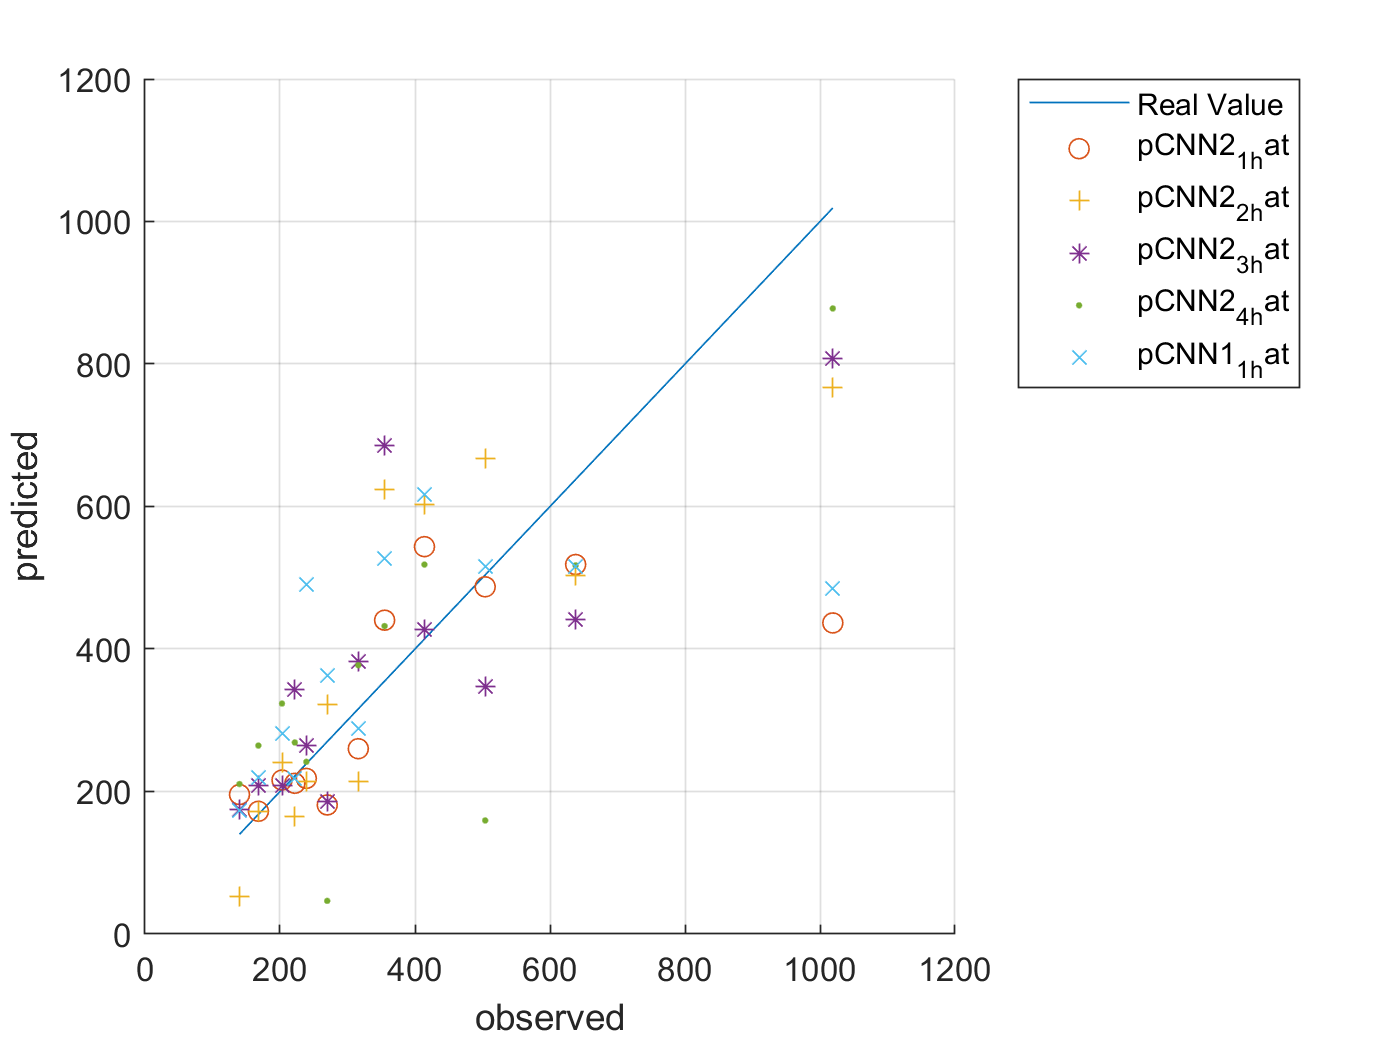




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
plot(ytest,pCNN2_3_hat,'*')
plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN2_3_hat', ... 	
		'pCNN2_4_hat', ... 
		'pCNN1_1_hat','Location','northeastoutside')



save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_2' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_3' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_4' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN1_1' ,'-append')



cellx_self = num2cell(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
pCNN2_3_self = predict(netCNN2_3, x_4d_self);
pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm_IcFirst_RUL([tr.trainInd tr.valInd], :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_1_self_hat = pCNN2_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_2_self_hat = pCNN2_2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_3_self_hat = pCNN2_3_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_4_self_hat = pCNN2_4_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN1_1_self_hat = pCNN1_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;



rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
173.1440

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
146.9517

rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))

rmse_pCNN2_3_self_hat = single
150.2192

rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))

rmse_pCNN2_4_self_hat = single
185.0792

rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
173.9875

ytrain_self_diff_percentage_CNN2_1_self_hat_avg = sum(abs(ytrain_self'-pCNN2_1_self_hat')./ytrain_self')/length(abs(ytrain_self'-pCNN2_1_self_hat')./ytrain_self')

ytrain_self_diff_percentage_CNN2_1_self_hat_avg = single
0.2856

ytrain_self_diff_percentage_CNN2_2_self_hat_avg = sum(abs(ytrain_self'-pCNN2_2_self_hat')./ytrain_self')/length(abs(ytrain_self'-pCNN2_2_self_hat')./ytrain_self')

ytrain_self_diff_percentage_CNN2_2_self_hat_avg = single
0.2669

ytrain_self_diff_percentage_CNN2_3_self_hat_avg = sum(abs(ytrain_self'-pCNN2_3_self_hat')./ytrain_self')/length(abs(ytrain_self'-pCNN2_3_self_hat')./ytrain_self')

ytrain_self_diff_percentage_CNN2_3_self_hat_avg = single
0.3445

ytrain_self_diff_percentage_CNN2_4_self_hat_avg = sum(abs(ytrain_self'-pCNN2_4_self_hat')./ytrain_self')/length(abs(ytrain_self'-pCNN2_4_self_hat')./ytrain_self')

ytrain_self_diff_percentage_CNN2_4_self_hat_avg = single
0.3847

ytrain_self_diff_percentage_CNN1_1_self_hat_avg = sum(abs(ytrain_self'-pCNN1_1_self_hat')./ytrain_self')/length(abs(ytrain_self'-pCNN1_1_self_hat')./ytrain_self')

ytrain_self_diff_percentage_CNN1_1_self_hat_avg = single
0.3856

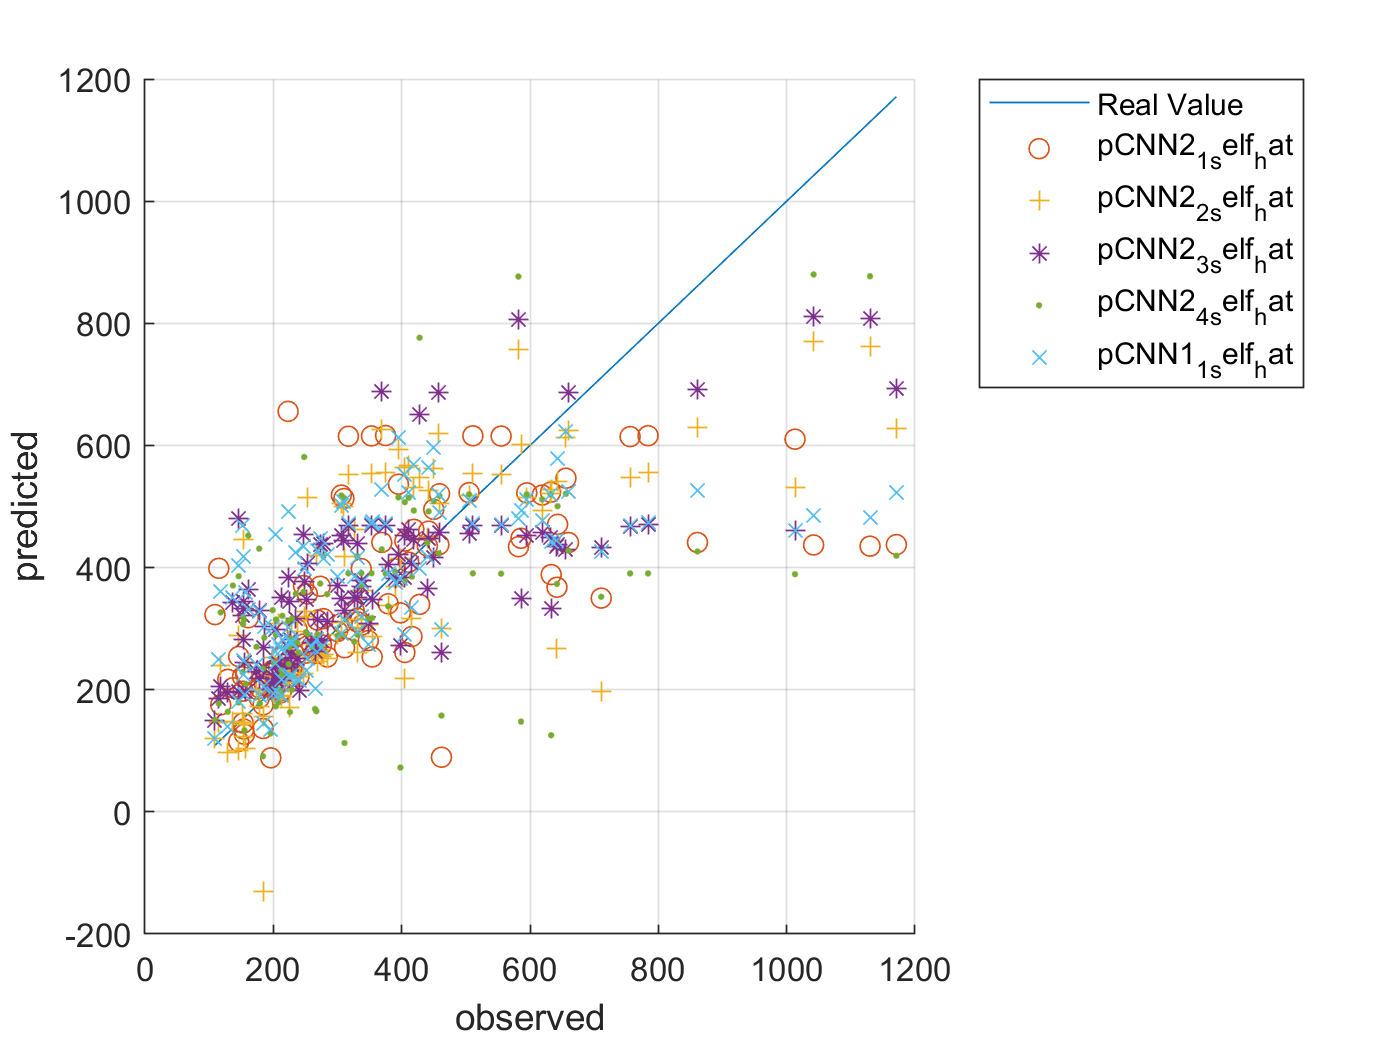



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
plot(ytrain_self,pCNN2_3_self_hat,'*')
plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN2_3_self_hat', ... 	
		'pCNN2_4_self_hat', ... 
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |         0.33 |         0.33 |       0.0528 |       0.0543 |          0.0010 |
|      50 |          50 |       00:00:15 |         0.20 |         0.22 |       0.0202 |       0.0251 |          0.0010 |
|     100 |         100 |       00:00:18 |         0.20 |         0.22 |       0.0196 |       0.0249 |          0.0010 |
|     150 |         150 |       00:00:20 |         0.20 |         0.22 |       0.0191 |       0.0245 |          0.0010 |
|     20

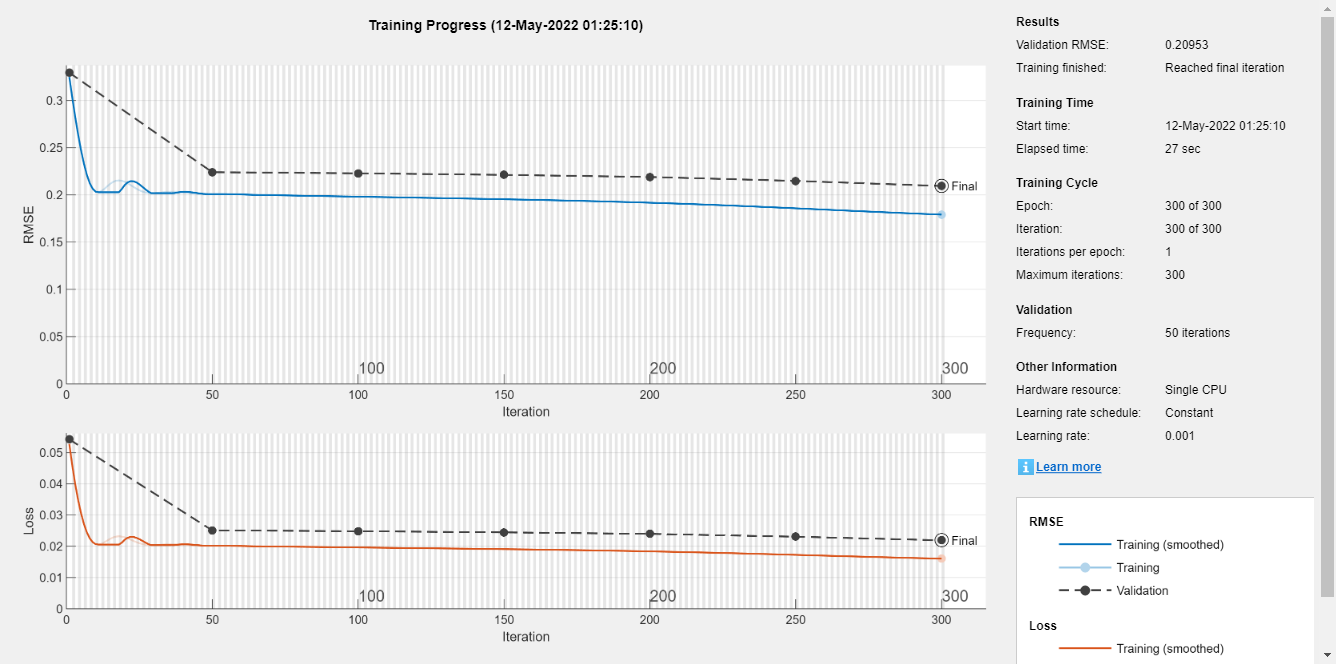

cc_input_size = 20;
numHiddenUnits = 50;

layersLSTM1 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm_IcFirstSmall_RUL', 1)';
cellyB = num2cell(ynorm_IcFirst_RUL);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',300, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM1 = trainNetwork(traincellx, traincellyB, layersLSTM1, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |         0.31 |         0.33 |       0.0473 |       0.0538 |          0.0010 |
|      50 |          50 |       00:00:23 |         0.20 |         0.23 |       0.0198 |       0.0254 |          0.0010 |
|     100 |         100 |       00:00:29 |         0.19 |         0.22 |       0.0189 |       0.0250 |          0.0010 |
|     150 |         150 |       00:00:33 |         0.19 |         0.22 |       0.0189 |       0.0249 |          0.0010 |
|     20

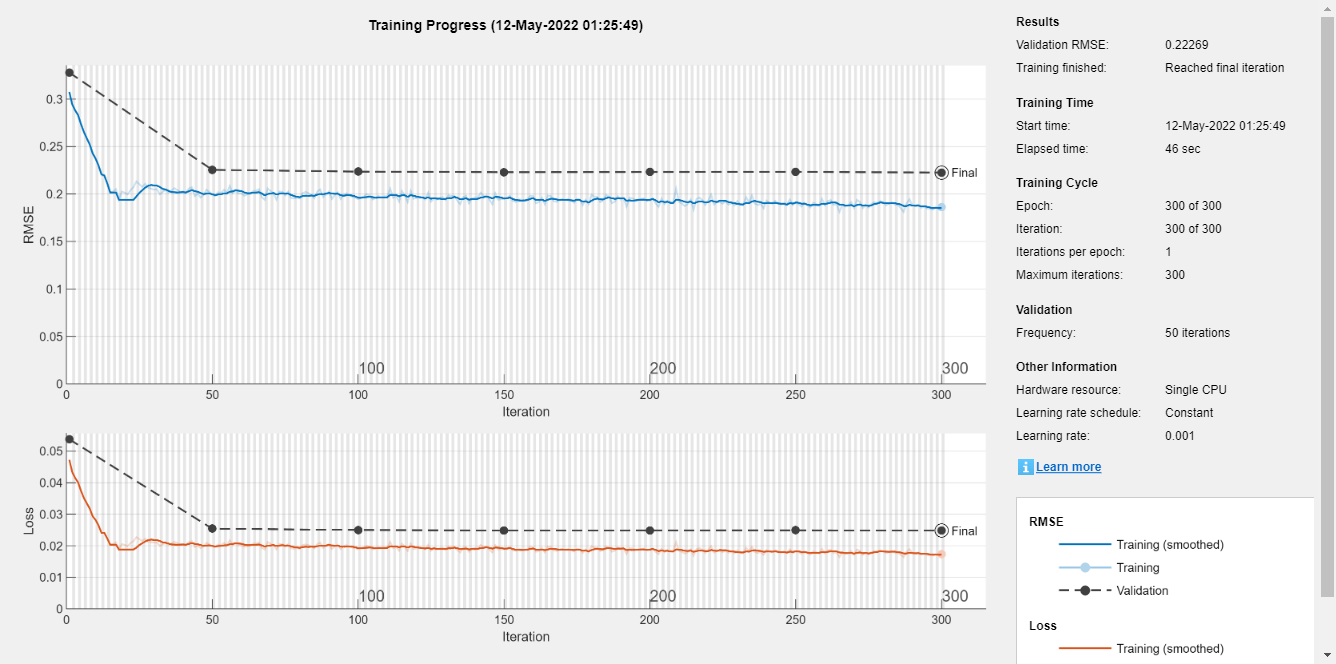

netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);


pLSTM1 = cell2mat(predict(netLSTM1, num2cell(xnorm_IcFirstSmall_RUL(tr.testInd, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_IcFirstSmall_RUL(tr.testInd, :)', 1)));
ytest = ynorm_IcFirst_RUL(tr.testInd, :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM1_hat = pLSTM1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM2_hat = pLSTM2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
rmse_pLSTM1_hat = sqrt(mean(( ytest' - pLSTM1_hat' ).^2))

rmse_pLSTM1_hat = single
217.4355

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM2_hat' ).^2))

rmse_pLSTM2_hat = single
224.4013

y_test_diff_percentage_LSTM_hat_avg = sum(abs(y_test'-pLSTM1_hat')./y_test')/length(abs(y_test'-pLSTM1_hat')./y_test')

y_test_diff_percentage_LSTM_hat_avg = single
0.3834

y_test_diff_percentage_LSTM2_hat_avg = sum(abs(y_test'-pLSTM2_hat')./y_test')/length(abs(y_test'-pLSTM2_hat')./y_test')

y_test_diff_percentage_LSTM2_hat_avg = single
0.3826

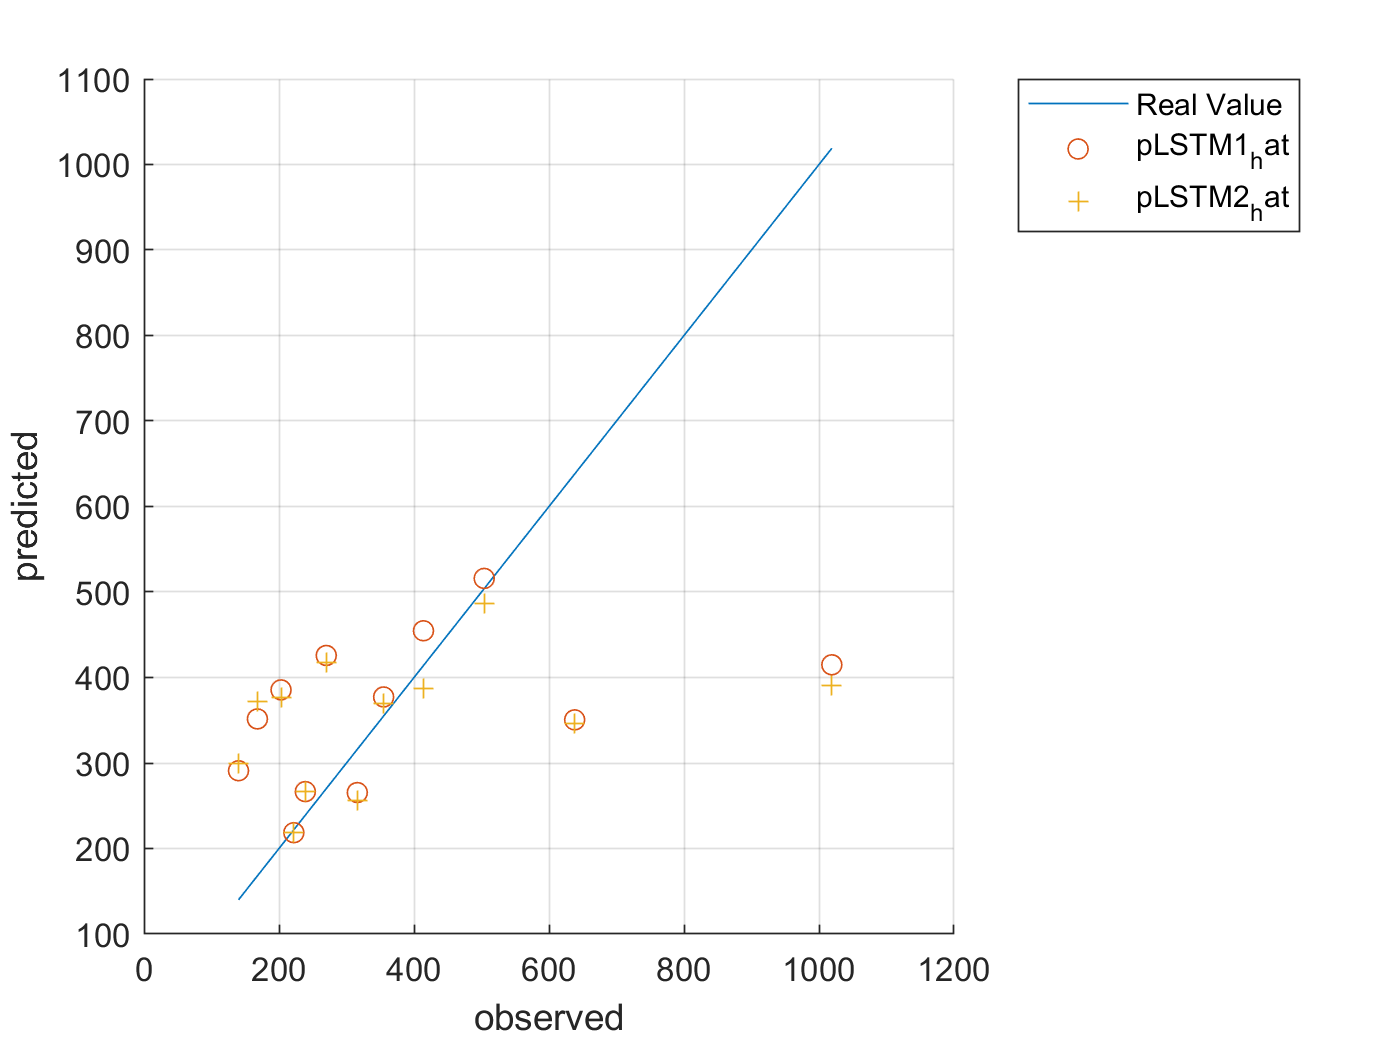


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM1_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM1_hat', ...
        'pLSTM2_hat','Location','northeastoutside')


save('ryan3_model_gen_FirstCC_RUL.mat','netLSTM1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netLSTM2' ,'-append')


pLSTM1_self = cell2mat(predict(netLSTM1, num2cell(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_IcFirstSmall_RUL([tr.trainInd tr.valInd], :)', 1)));
ytrain_self = ynorm_IcFirst_RUL([tr.trainInd tr.valInd], :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM1_self = pLSTM1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM2_self = pLSTM2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
rmse_pLSTM1_self_hat = sqrt(mean(( ytrain_self' - pLSTM1_self' ).^2))

rmse_pLSTM1_self_hat = single
202.3366

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
212.9790

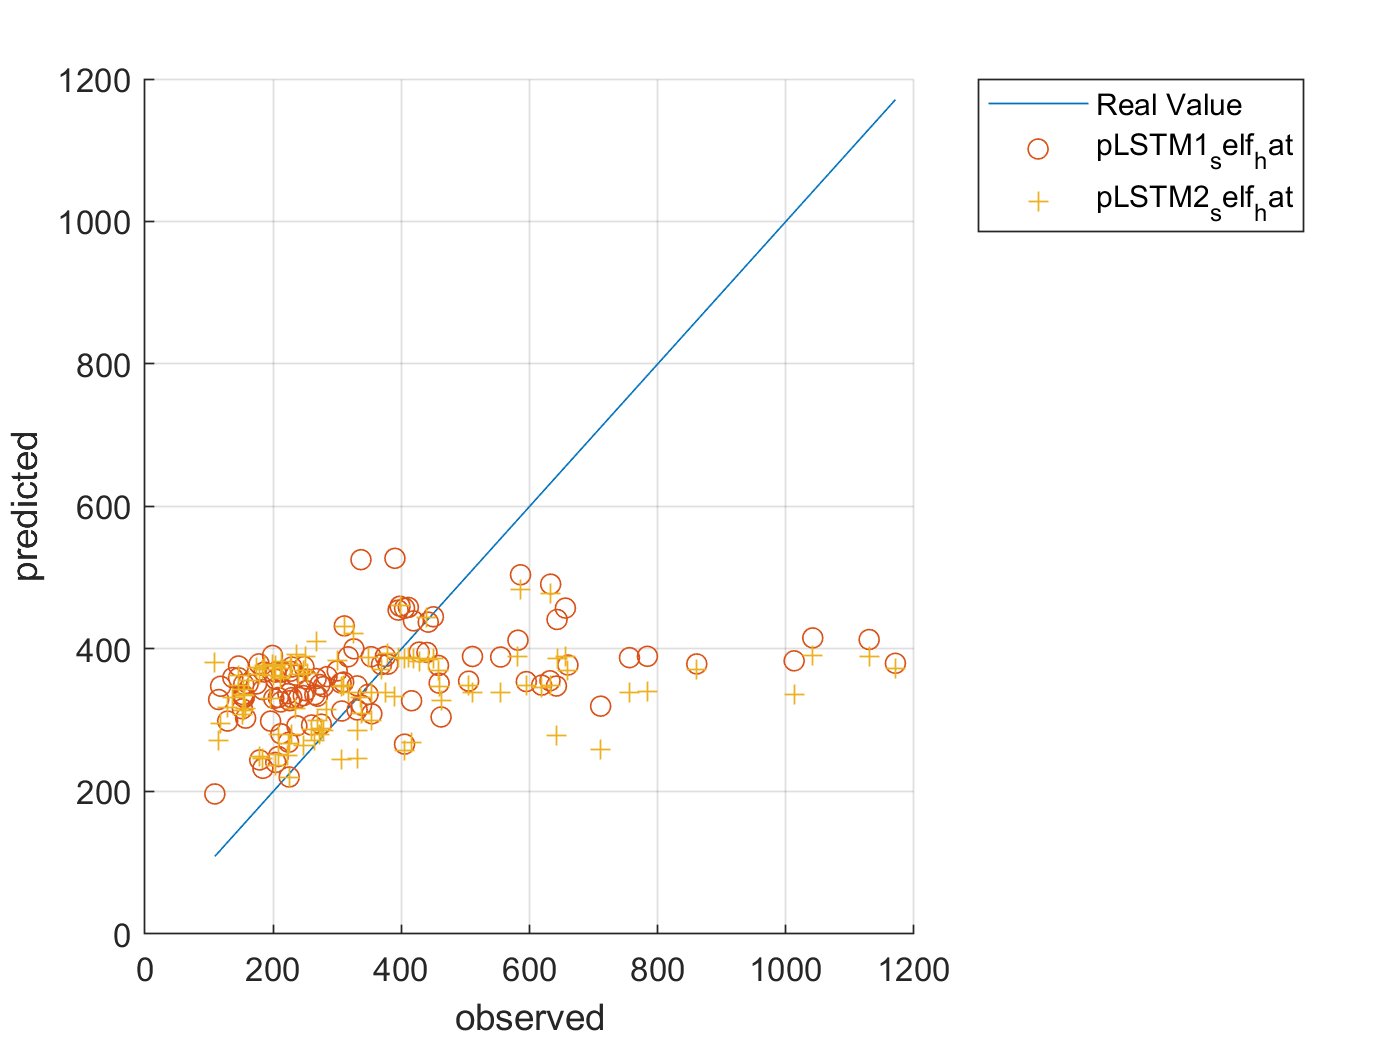


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM1_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM1_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')

%{
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_2' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_3' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN2_4' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netCNN1_1' ,'-append')


save('ryan3_model_gen_FirstCC_RUL.mat','netLSTM1' ,'-append')
save('ryan3_model_gen_FirstCC_RUL.mat','netLSTM2' ,'-append')
%}